# CUMCM2022 C 题 讲评 

华南理工大学  数学学院 数模团队 曾才斌

2023 年 5 月 16 日

## 一、问题背景

出题人：西安建筑科技大学 鲁萍

丝绸之路是古代中西方文化交流的通道，其玻璃早期贸易往来宝贵物证。

国内外的古代玻璃的外观相似，但化学成分却不相同。

古代玻璃的主要化学成分是二氧化硅，但纯石英砂熔点较高，需要添加助熔剂，可表现为铅钡玻璃、高钾玻璃等。

出土的古代玻璃极易受到埋藏环境的影响而风化，从而影响对其类别的正确判断。

成分数据：具有定和约束，成分数据各分量之间具有明显的共线性，导致常规的统计方法失效。

[陈晖 2021 硕士论文《单形空间中多元成分数据的回归建模方法研究》](https://kns.cnki.net/kcms2/article/abstract?v=3uoqIhG8C475KOm_zrgu4lQARvep2SAkaWjBDt8_rTOnKA7PWSN5MOsZxiOPJOqQd0FKJwDABgmIyAGb_MhBiyRw62LUqZXr&uniplatform=NZKPT)

[罗纯 2011 硕士论文《基于成分数据若干分析方法的研究》](https://kns.cnki.net/kcms2/article/abstract?v=3uoqIhG8C475KOm_zrgu4lQARvep2SAkWGEmc0QetxDh64Dt3veMp2170R2XhorfBBa58lh8uYq5acrLwPkEsfvPig7ZMrVq&uniplatform=NZKPT)

[优秀论文 C155 （来源：中国大学生在线）](https://dxs.moe.gov.cn/zx/a/hd_sxjm_sxjmlw_2022qgdxssxjmjslwzs/221106/1820281.shtml) （SPSSPRO、Matlab、Python、R等编写代码）

[优秀论文 C229（来源：中国大学生在线）](https://dxs.moe.gov.cn/zx/a/hd_sxjm_sxjmlw_2022qgdxssxjmjslwzs/221106/1820279.shtml?source=hd_sxjm_sxjmlw_2022qgdxssxjmjslwzs)  (R 编写代码)

[常用的数据分析方法汇总（来源：知乎）](https://zhuanlan.zhihu.com/p/39214084)

## 二、问题重述

问题 1：根据所给古代玻璃制品的相关数据，分析这些玻璃的表面风化与其玻璃类型、纹饰和颜色的关系；结合玻璃的类型，对文物样品表面有无风化的化学成分含量的统计规律进行分析，并根据风化点检测数据，预测其风化前的化学成分含量。

问题 2：基于附件数据，分析高钾玻璃、铅钡玻璃的分类规律；对于每个类别进行的亚类划分，给出具体的划分方法及划分结果，并分析分类结果的合理性和敏感性。

问题 3：基于附件数据，分析未知类别玻璃文物的化学成分，鉴别其所属类别并分析结果的敏感性。

问题 4：针对不同类别的玻璃样品，对其化学成分之间的关联关系进行分析，并比较不同类别的化学成分关联关系的差异性。

## 三、问题分析

### 3.1 问题 1 的分析

本小问需要分析玻璃的表面风化与其玻璃类型、纹饰和颜色的关系，首先对数据进行预处理，包括量化处理、无效数据删除处理、空缺数据填充处理、归一化处理，并利用中心对数比变换方法处理归一化后的成分数据。其次，根据卡方检验的适用条件，拟采用合理的方法（Pearson 卡方检验、Yates 校正卡方检验、Fisher 确切检验）来分析这些玻璃的表面风化与其玻璃类型、纹饰和颜色的关系 。进一步，针对中心对数比变换后的化学成分数据，拟引入均值、最大值、最小值、标准差、变异系数、偏度系数、峰度系数来分析。由于缺乏风化前后匹配的数据，拟采用两总体的非参检验，预测风化前的化学成分含量，并利用中心对数比逆变换还原为成分数据。

### 3.2 问题 2 的分析

本小问首先将中心对数比变换后的化学成分数据划分为无风化和风化两类，拟采用自适应优化参数的决策树算法，分析高钾玻璃与铅钡玻璃的分类条件。其次，亚类划分属于无监督分类问题，拟结合Q型聚类和R型聚类方法进行讨论，同时在对原数据进行小扰动，观察结果的波动性来获得敏感性结果。

### 3.3 问题 3 的分析

本小问要求鉴别 8 个古玻璃的所属类别，拟采用问题 2 训练好的决策树进行分类，并类似问题 2 第 3 小问做敏感性分析。

### 3.4 问题 4 的分析

为了分析不同类别的玻璃的化学成分之间的关联关系，拟采用 Pearson 相关系数分析和灰色关联度分析法，依次选取一项化学成分作为母序列，其他十三项作为子序列，并对关联系数加权处理而获得关联度值。其次拟采用 Wilcoxon 秩和检验来分析高钾玻璃和铅钡玻璃两个类别的化学成分的差异性。

## 四、数据预处理

% 清除工作区、命令行窗口
clear; clc;

### **4.1 表单 1 的数据预处理**

- **颜色缺失填充**：

颜色缺失的编号：19、40、48、58

观察到 19、48 的其他信息为： 纹饰 A、铅钡玻璃、风化，同样信息的其他编号也是随意采用，故采用众数方法，填充为浅蓝。 

 观察到 40、58 的其他信息为： 纹饰 C、铅钡玻璃、风化 ，同样信息的其他编号有特殊采样点，根据成分的相似原则，分别填充为深绿、浅蓝。

- **量化处理：**

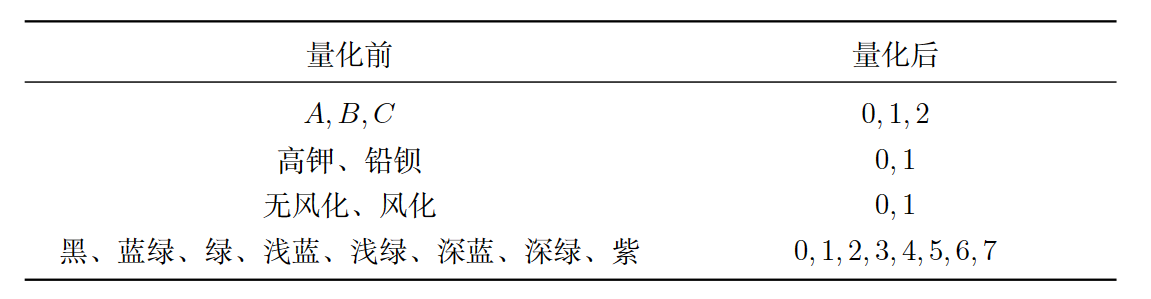

T1 = Predata1  

T1 = 58×4 table
    ORNA    TYPE    COLOR    WEAT
    ____    ____    _____    ____

     2       0        1       0  
     0       1        3       1  
     0       0        1       0  
     0       0        1       0  
     0       0        1       0  
     0       0        1       0  
     1       0        1       1  
     2       1        7       1  
     1       0        1       1  
     1       0        1       1  
     2       1        3       1  
     1       0        1       1  
     2       0        3       0  
     2       0        6       0  
     2       0        3       0  
     2       0        3       0  


### **4.2 表单 2 的数据预处理**

将表单 2 对应编号的玻璃类型和表面风化的数据导入，特别注意同一编号的多个采样点的数据，进行量化处理、缺失值与零值都替换为 eps，目的是为后续合理利用中心对数比变换。

[T2data, T2all] = Predata2

T2data =    69.3300    0.0000    9.9900    6.3200    0.8700    3.9300    1.7400    3.8700    0.0000    0.0000    1.1700    0.0000    0.0000    0.3900
   36.2800    0.0000    1.0500    2.3400    1.1800    5.7300    1.8600    0.2600   47.4300    0.0000    3.5700    0.1900    0.0000    0.0000
   87.0500    0.0000    5.1900    2.0100    0.0000    4.0600    0.0000    0.7800    0.2500    0.0000    0.6600    0.0000    0.0000    0.0000
   61.7100    0.0000   12.3700    5.8700    1.1100    5.5000    2.1600    5.0900    1.4100    2.8600    0.7000    0.1000    0.0000    0.0000
   65.8800    0.0000    9.6700    7.1200    1.5600    6.4400    2.0600    2.1800    0.0000    0.0000    0.7900    0.0000    0.0000    0.3600
   61.5800    0.0000   10.9500    7.3500    1.7700    7.5000    2.6200    3.2700    0.0000    0.0000    0.9400    0.0600    0.0000    0.4700
   67.6500    0.0000    7.3700    0.0000    1.9800   11.1500    2.3900    2.5100    0.2000    1.3800    4.1800    0.1100    0.0000    0.0000
   5

T2all = 69×17 table
        NO         TYPE    WEAT    SiO2        Na2O          K2O           CaO           MgO        Al2O3      Fe2O3        CuO        PbO           BaO           P2O5          SrO           SnO2          SO2    
    ___________    ____    ____    _____    __________    __________    __________    __________    _____    __________    _____    __________    __________    __________    __________    __________    __________

    01              0       0      69.33    2.2204e-16          9.99          6.32          0.87     3.93          1.74     3.87    2.2204e-16    2.2204e-16          1.17    2.2204e-16    2.2204e-16          0.39
    02              1       1      36.28    2.2204e-16          1.05          2.34          1.18     5.73          1.86     0.26         47.43    2.2204e-16          3.57          0.19    2.2204e-16    2.2204e-16
    03部位1         0       0      87.05    2.2204e-16          5.19          2.01    2.2204e-16     4.06    2.2204e-16     0.78 

删除无效数据  （$[85, 105]$为有效数据）

T2valid = sum(T2data,2);
ind = find(T2valid < 85 | T2valid > 105);
T2data(ind,:) = [];
T2valid(ind) = [];
T2all(ind,:) = [];

归一化 $C(x_i) =\frac{100 x_i}{\sum_{i=1}^px_i}$

T2comp = 100*T2data./T2valid

T2comp =    71.0276    0.0000   10.2346    6.4747    0.8913    4.0262    1.7826    3.9648    0.0000    0.0000    1.1986    0.0000    0.0000    0.3995
   36.3200    0.0000    1.0512    2.3426    1.1813    5.7363    1.8620    0.2603   47.4822    0.0000    3.5739    0.1902    0.0000    0.0000
   87.0500    0.0000    5.1900    2.0100    0.0000    4.0600    0.0000    0.7800    0.2500    0.0000    0.6600    0.0000    0.0000    0.0000
   62.4090    0.0000   12.5101    5.9365    1.1226    5.5623    2.1845    5.1477    1.4260    2.8924    0.7079    0.1011    0.0000    0.0000
   68.5821    0.0000   10.0666    7.4120    1.6240    6.7041    2.1445    2.2694    0.0000    0.0000    0.8224    0.0000    0.0000    0.3748
   63.8069    0.0000   11.3460    7.6158    1.8340    7.7712    2.7147    3.3882    0.0000    0.0000    0.9740    0.0622    0.0000    0.4870
   68.3886    0.0000    7.4505    0.0000    2.0016   11.2717    2.4161    2.5374    0.2022    1.3951    4.2256    0.1112    0.0000    0.0000
   6

由于成分数据的特点，必须引入中心对数比变换

单形空间  $S = \left\{(x_1,x_2,\ldots,x_p): x_i>0, \sum_{i=1}^px_i=1\right\}$

中心对数比变换 $\left(z_1, z_2,\cdots, z_p\right) = \left(\log\left( \frac{x_1}{g(x)}\right), \log\left( \frac{x_2}{g(x)}\right)\log, \cdots, \left( \frac{x_p}{g(x)}\right)\right), \quad i=1,2,\ldots,p, \quad g(x)=\sqrt[p]{\prod_{i=1}^px_i}$

中心对数比逆变换 $\left(x_1, x_2, \cdots, x_p\right) = \left(\frac{100e^{z_1}}{\sum_^{i=1}^pe^{z_i} }, \frac{100e^{z_2}}{\sum_^{i=1}^pe^{z_i} },\cdots,\frac{100e^{z_p}}{\sum_^{i=1}^pe^{z_i} }\right)$

T2clr = log(T2comp./geomean(T2comp,2))

T2clr =    16.3447  -23.9378   14.4075   13.9496   11.9666   13.4745   12.6598   13.4591  -23.9378  -23.9378   12.2629  -23.9378  -23.9378   11.1643
   13.2362  -26.3988    9.6937   10.4950    9.8104   11.3906   10.2655    8.2978   13.5042  -26.3988   10.9175    7.9842  -26.3988  -26.3988
   22.0481  -18.4620   19.2284   18.2798  -18.4620   18.9828  -18.4620   17.3332   16.1954  -18.4620   17.1661  -18.4620  -18.4620  -18.4620
   11.0354  -29.1307    9.4283    8.6828    7.0173    8.6177    7.6831    8.5403    7.2566    7.9638    6.5563    4.6104  -29.1307  -29.1307
   16.2769  -23.9546   14.3581   14.0520   12.5337   13.9516   12.8118   12.8684  -23.9546  -23.9546   11.8533  -23.9546  -23.9546   11.0674
   13.7320  -26.4320   12.0050   11.6063   10.1826   11.6265   10.5748   10.7964  -26.4320  -26.4320    9.5497    6.7982  -26.4320    8.8566
   13.8673  -26.3907   11.6504  -26.3907   10.3360   12.0644   10.5242   10.5732    8.0435    9.9750   11.0832    7.4457  -26.3907  -26.3907
   10

### 4.3 表单 3 的数据预处理

量化处理、缺失值与零值都替换为 eps

[T3data,T3all] = Predata3

T3data =    78.4500    0.0000    0.0000    6.0800    1.8600    7.2300    2.1500    2.1100    0.0000    0.0000    1.0600    0.0300    0.0000    0.5100
   37.7500    0.0000    0.0000    7.6300    0.0000    2.3300    0.0000    0.0000   34.3000    0.0000   14.2700    0.0000    0.0000    0.0000
   31.9500    0.0000    1.3600    7.1900    0.8100    2.9300    7.0600    0.2100   39.5800    4.6900    2.6800    0.5200    0.0000    0.0000
   35.4700    0.0000    0.7900    2.8900    1.0500    7.0700    6.4500    0.9600   24.2800    8.3100    8.4500    0.2800    0.0000    0.0000
   64.2900    1.2000    0.3700    1.6400    2.3400   12.7500    0.8100    0.9400   12.2300    2.1600    0.1900    0.2100    0.4900    0.0000
   93.1700    0.0000    1.3500    0.6400    0.2100    1.5200    0.2700    1.7300    0.0000    0.0000    0.2100    0.0000    0.0000    0.0000
   90.8300    0.0000    0.9800    1.1200    0.0000    5.0600    0.2400    1.1700    0.0000    0.0000    0.1300    0.0000    0.0000    0.1100
   5

T3all = 8×16 table
    NO    WEAT    SiO2        Na2O          K2O        CaO        MgO        Al2O3      Fe2O3          CuO           PbO           BaO        P2O5        SrO           SnO2          SO2    
    __    ____    _____    __________    __________    ____    __________    _____    __________    __________    __________    __________    _____    __________    __________    __________

    A1     0      78.45    2.2204e-16    2.2204e-16    6.08          1.86     7.23          2.15          2.11    2.2204e-16    2.2204e-16     1.06          0.03    2.2204e-16          0.51
    A2     1      37.75    2.2204e-16    2.2204e-16    7.63    2.2204e-16     2.33    2.2204e-16    2.2204e-16          34.3    2.2204e-16    14.27    2.2204e-16    2.2204e-16    2.2204e-16
    A3     0      31.95    2.2204e-16          1.36    7.19          0.81     2.93          7.06          0.21         39.58          4.69     2.68          0.52    2.2204e-16    2.2204e-16
    A4     0      35.47    2.2

归一化

T3comp = 100*T3data./sum(T3data,2)

T3comp =    78.8601    0.0000    0.0000    6.1118    1.8697    7.2678    2.1612    2.1210    0.0000    0.0000    1.0655    0.0302    0.0000    0.5127
   39.2086    0.0000    0.0000    7.9248    0.0000    2.4200    0.0000    0.0000   35.6253    0.0000   14.8214    0.0000    0.0000    0.0000
   32.2792    0.0000    1.3740    7.2641    0.8183    2.9602    7.1328    0.2122   39.9879    4.7383    2.7076    0.5254    0.0000    0.0000
   36.9479    0.0000    0.8229    3.0104    1.0937    7.3646    6.7187    1.0000   25.2917    8.6562    8.8021    0.2917    0.0000    0.0000
   64.5352    1.2046    0.3714    1.6463    2.3489   12.7986    0.8131    0.9436   12.2767    2.1682    0.1907    0.2108    0.4919    0.0000
   94.0161    0.0000    1.3623    0.6458    0.2119    1.5338    0.2725    1.7457    0.0000    0.0000    0.2119    0.0000    0.0000    0.0000
   91.1582    0.0000    0.9835    1.1240    0.0000    5.0783    0.2409    1.1742    0.0000    0.0000    0.1305    0.0000    0.0000    0.1104
   5

中心对数比变换

T3clr = log(T3comp./geomean(T3comp,2))

T3clr =    16.7954  -23.6107  -23.6107   14.2380   13.0535   14.4112   13.1984   13.1796  -23.6107  -23.6107   12.4912    8.9264  -23.6107   11.7596
   25.8946  -13.7800  -13.7800   24.2957  -13.7800   23.1095  -13.7800  -13.7800   25.7988  -13.7800   24.9218  -13.7800  -13.7800  -13.7800
   10.2908  -29.2170    7.1341    8.7993    6.6159    7.9016    8.7811    5.2660   10.5050    8.3721    7.8125    6.1727  -29.2170  -29.2170
   10.2644  -29.3479    6.4600    7.7570    6.7445    8.6516    8.5598    6.6549    9.8854    8.8132    8.8299    5.4228  -29.3479  -29.3479
    6.2873    2.3063    1.1297    2.6186    2.9741    4.6695    1.9132    2.0621    4.6278    2.8940    0.4632    0.5633    1.4106  -33.9197
   19.9157  -20.6624   15.6814   14.9350   13.8206   15.8000   14.0719   15.9294  -20.6624  -20.6624   13.8206  -20.6624  -20.6624  -20.6624
   19.9059  -20.6468   15.3767   15.5102  -20.6468   17.0182   13.9697   15.5539  -20.6468  -20.6468   13.3566  -20.6468  -20.6468   13.1896
   13

## 五、模型建立和求解

### 5.1 问题 1 的模型建立与求解

#### 5.1.1 问题 1 第 1 小问：RC交叉表检验

卡方检验：在一定的置信水平和自由度下，通过比较卡方统计量和卡方分布函数概率值，判断实际概率与期望概率是否吻合，通过比较理论概率和实际概率的吻合程度，可检验两个分类变量的相关性。

卡方检验的适用条件：

（1）若样本总数 $$n\ge40$$，且任意一个格子的理论频数 $$T_{ij}\ge5$$，采用卡方检验公式；

（2）若样本总数 $$n\ge40$$，但出现一个格子的理论频数 $$1\le T_{ij}<5$$，采用 Yates 校正检验公式；

（3）若样本总数 $$n<40$$或者任意一个格子的理论频数 $$T_{ij}<1$$，采用 Fisher 确切检验公式；

% 按表面风化--纹饰的期望计数
AWO = crosstab(T1.WEAT,T1.ORNA);
disp('表面风化--纹饰 RC 交叉表检验：')

表面风化--纹饰 RC 交叉表检验：


chi2check(AWO)

样本总数为 58
最小的期望计数为 2.4828
采用 Yates 校正卡方检验公式


% 按表面风化--颜色的期望计数
TCnovalid = find(T1.COLOR == "8");
COLORvalid = T1.COLOR(setdiff(1:size(T1.COLOR,1), TCnovalid));
WEATvalid = T1.WEAT(setdiff(1:size(T1.COLOR,1), TCnovalid));
AWC = crosstab(WEATvalid,double(COLORvalid));
disp('表面风化--颜色 RC 交叉表检验：')

表面风化--颜色 RC 交叉表检验：


chi2check(AWC)

样本总数为 58
最小的期望计数为 0.4138
采用 Fisher 确切检验公式


% 按表面风化--玻璃类型的期望计数
AWT = crosstab(T1.WEAT,T1.TYPE);
disp('表面风化--玻璃类型 RC 交叉表检验：')

表面风化--玻璃类型 RC 交叉表检验：


chi2check(AWT)

样本总数为 58
最小的期望计数为 7.4483
采用卡方检验公式


% 表面风化--纹饰的Yates校正卡方检验
[~,WOstat,WOp] = crosstab(T1.WEAT,T1.ORNA);
fprintf('表面风化--纹饰的 Yates 校正卡方检验的统计量为 %.4f，p 值为 %.4f',WOstat,WOp);

表面风化--纹饰的 Yates 校正卡方检验的统计量为 4.9565，p 值为 0.0839

% 表面风化--颜色的Fisher确切检验
[~,WCstat,WCp] = crosstab(WEATvalid,double(COLORvalid));
fprintf('表面风化--颜色的 Fisher 确切检验的统计量为 %.4f，p 值为 %.4f',WCstat,WCp);

表面风化--颜色的 Fisher 确切检验的统计量为 7.0492，p 值为 0.4238

% 表面风化--玻璃类型的卡方检验
[AWT,WTstat,WTp] = crosstab(T1.WEAT,T1.TYPE);
fprintf('表面风化--玻璃类型的卡方检验的统计量为 %.4f，p 值为 %.4f',WTstat,WTp);

表面风化--玻璃类型的卡方检验的统计量为 6.8804，p 值为 0.0087

结论：玻璃表面风化与玻璃类型有关联，与纹饰、颜色不相关。

#### 5.1.2 问题 1 第 2 小问：不同玻璃的化学成分的统计规律

采用中心对数比变换化的数据

高钾无风化、高钾风化、铅钡无风化、铅钡风化的十四个指标的统计规律

% 分类: 高钾无风化、高钾风化、铅钡无风化、铅钡风化
Q1 = T2all(:,2:3);
Q00 = T2clr((Q1.TYPE == "0" & Q1.WEAT == "0"),:); % 高钾无风化
Q01 = T2clr((Q1.TYPE == "0" & Q1.WEAT == "1"),:); % 高钾风化
Q10 = T2clr((Q1.TYPE == "1" & Q1.WEAT == "0"),:); % 铅钡无风化
Q11 = T2clr((Q1.TYPE == "1" & Q1.WEAT == "1"),:); % 铅钡风化

统计规律: 均值、最小值、最大值、标准差、变异系数、偏度系数、峰度系数

%  高钾无风化
[Q00mean,Q00min,Q00max,Q00std,Q00vc,Q00skew,Q00kurt] = StatAll(Q00);
% 可视化结果
CompNames = ['SiO_2', "Na_2O", "K_2O", "CaO", "MgO", "Al_2O_3", ...
    "Fe_2O_3", "Cu_O", "PbO", "BaO", "P_2O_5", "SrO", "SnO_2", "SO_2"];
StatNames = ["均值","最小值","最大值","标准差","变异系数","偏度系数","峰度系数"];
Q00tab = table(Q00mean',Q00min',Q00max',Q00std',Q00vc',Q00skew',Q00kurt');
Q00tab.Properties.VariableNames = StatNames;
Q00tab.Properties.RowNames = CompNames

Q00tab = 14×7 table
                均值       最小值      最大值     标准差     变异系数    偏度系数     峰度系数
               _______    _______    _______    ______    _______    ________    _______

    SiO_2       15.741     10.989     22.427    3.8899     24.713     0.69256     2.5876
    Na_2O      -14.415    -29.145     15.463    17.598    -122.08      1.0545     2.1915
    K_2O        13.605     8.9369     19.228    3.3309     24.483     0.34612     2.2106
    CaO         9.7035    -26.391      18.28    12.401      127.8     -2.9093     12.084
    MgO         1.7982    -21.631     12.534     13.75     764.66     -1.1505     2.2737
    Al_2O_3      13.28     8.6177     18.983    3.3652     25.341     0.49249     2.4284
    Fe_2O_3     8.6058    -18.462     16.643    9.4196     109.46     -2.7542     11.497
    Cu_O         12.23     7.6776     18.382    3.6715      30.02     0.54423     1.9408
    PbO        -5.3524    -26.432     16.195    17.044    -318.44    -0.16908    0.80939
    BaO        -1

%  高钾风化
[Q01mean,Q01min,Q01max,Q01std,Q01vc,Q01skew,Q01kurt] = StatAll(Q01);
% 可视化结果
Q01tab = table(Q01mean',Q01min',Q01max',Q01std',Q01vc',Q01skew',Q01kurt');
Q01tab.Properties.VariableNames = StatNames;
Q01tab.Properties.RowNames = CompNames

Q01tab = 14×7 table
                均值       最小值      最大值     标准差     变异系数    偏度系数     峰度系数
               _______    _______    _______    ______    _______    ________    _______

    SiO_2        21.84     16.446     25.083    2.9805     13.647     -0.9187     3.8336
    Na_2O      -18.693    -23.938    -15.533    2.9157    -15.598    -0.90058     3.7346
    K_2O        2.0932    -23.938     20.428    20.232     966.56    -0.40257    0.44938
    CaO         12.205    -18.498     20.365    13.709     112.33     -2.5111     9.4498
    MgO         1.8404     -18.17     17.971    17.256     937.62    -0.34146    0.29074
    Al_2O_3     18.188     13.929      20.98    2.3694     13.028     -0.8817     3.7788
    Fe_2O_3     11.336    -18.498     19.164    13.336     117.64     -2.4987     9.4043
    Cu_O        12.553    -18.498     21.473    13.995     111.49     -2.4146     9.0553
    PbO        -13.544    -20.763     12.106    11.449    -84.532      2.5123     9.4725
    BaO        -1

% 铅钡无风化
[Q10mean,Q10min,Q10max,Q10std,Q10vc,Q10skew,Q10kurt] = StatAll(Q10);
% 可视化结果
Q10tab = table(Q10mean',Q10min',Q10max',Q10std',Q10vc',Q10skew',Q10kurt');
Q10tab.Properties.VariableNames = StatNames;
Q10tab.Properties.RowNames = CompNames

Q10tab = 14×7 table
                均值       最小值      最大值     标准差     变异系数     偏度系数     峰度系数
               _______    _______    _______    ______    _______    _________    _______

    SiO_2       14.087     8.7653     18.643    2.8147     19.981    -0.021632     2.5367
    Na_2O      -9.9126    -26.653     15.748    18.477    -186.39      0.36874    0.93799
    K_2O       -3.4208    -26.653     14.098    16.924    -494.73     -0.60835     1.2493
    CaO         5.2762    -23.709     14.873    12.067     228.71      -2.1237     6.3368
    MgO        -2.7506    -28.491     12.848    16.772    -609.76     -0.66565     1.2992
    Al_2O_3     11.406     7.2805     16.137    2.6087     22.871      0.21488     2.4978
    Fe_2O_3    -2.5049    -28.841     14.853    17.492     -698.3     -0.63298     1.2744
    Cu_O         5.023    -26.575     16.005    13.738      273.5      -2.0542      6.119
    PbO         13.428     7.1279     18.245    2.7839     20.732     -0.49443     4.0008
    Ba

 % 铅钡风化
[Q11mean,Q11min,Q11max,Q11std,Q11vc,Q11skew,Q11kurt] = StatAll(Q11);
% 可视化结果
Q11tab = table(Q11mean',Q11min',Q11max',Q11std',Q11vc',Q11skew',Q11kurt');
Q11tab.Properties.VariableNames = StatNames;
Q11tab.Properties.RowNames = CompNames

Q11tab = 14×7 table
                均值       最小值     最大值     标准差     变异系数     偏度系数     峰度系数
               _______    _______    ______    ______    _______    _________    _______

    SiO_2       14.251     8.3793     23.04    3.6053     25.298      0.52976    2.6323 
    Na_2O      -16.726    -31.137    16.263    15.124    -90.423        1.227    2.8024 
    K_2O       -10.264    -29.254    13.476    15.881    -154.71      0.25516     1.119 
    CaO         9.4117    -21.518    20.074    8.0856      85.91      -2.9133    12.654 
    MgO         -3.514    -26.746    17.315    16.596    -472.28     -0.39518    1.2273 
    Al_2O_3     11.859     6.4538    20.583    3.3658     28.382      0.66344    3.1702 
    Fe_2O_3    -6.8032    -28.873    13.798    16.758    -246.33    -0.070903    1.0301 
    Cu_O        9.0227    -31.641    19.952    9.6704     107.18      -3.1307    14.139 
    PbO         14.362     7.1571    23.613    3.8265     26.643      0.43893    2.8885 
    BaO         9

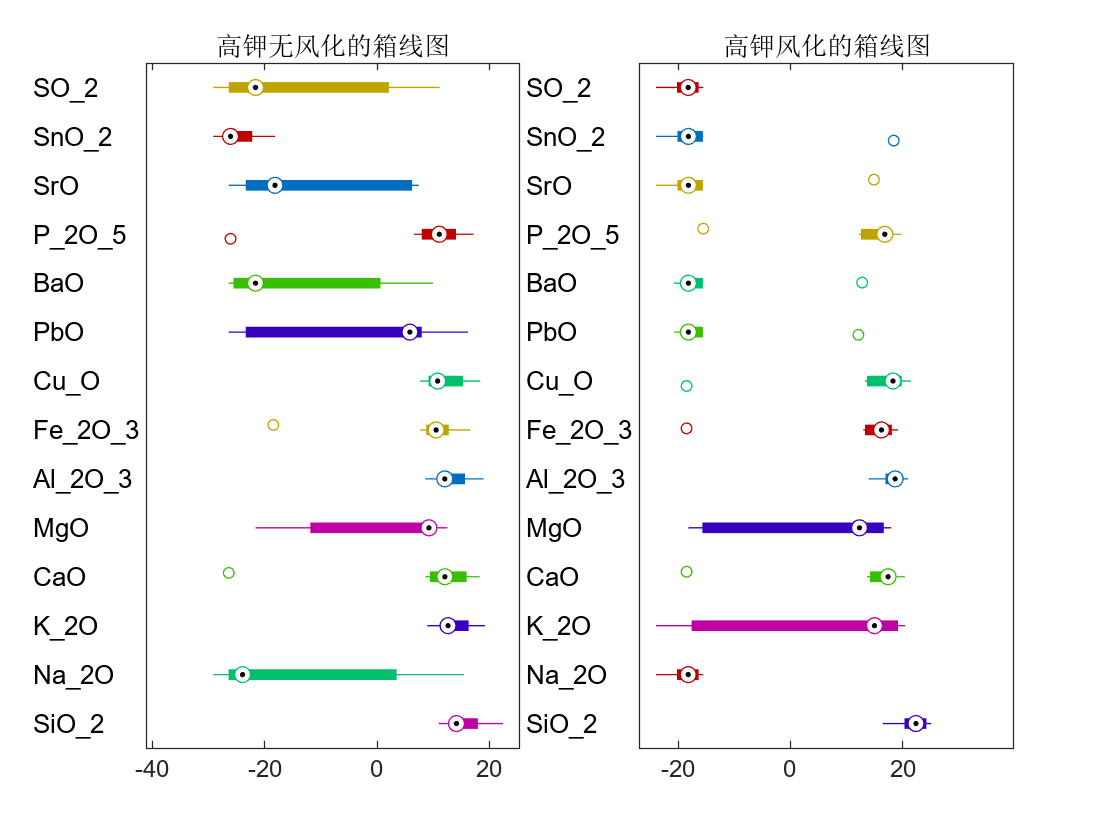

% 箱线图
subplot(121)
boxplot(Q00,'Labels',CompNames,'Orientation','horizontal','PlotStyle','compact','ColorGroup',Q00mean)
title('高钾无风化的箱线图')
subplot(122)
boxplot(Q01,'Labels',CompNames,'Orientation','horizontal','PlotStyle','compact','ColorGroup',Q01mean)
title('高钾风化的箱线图')

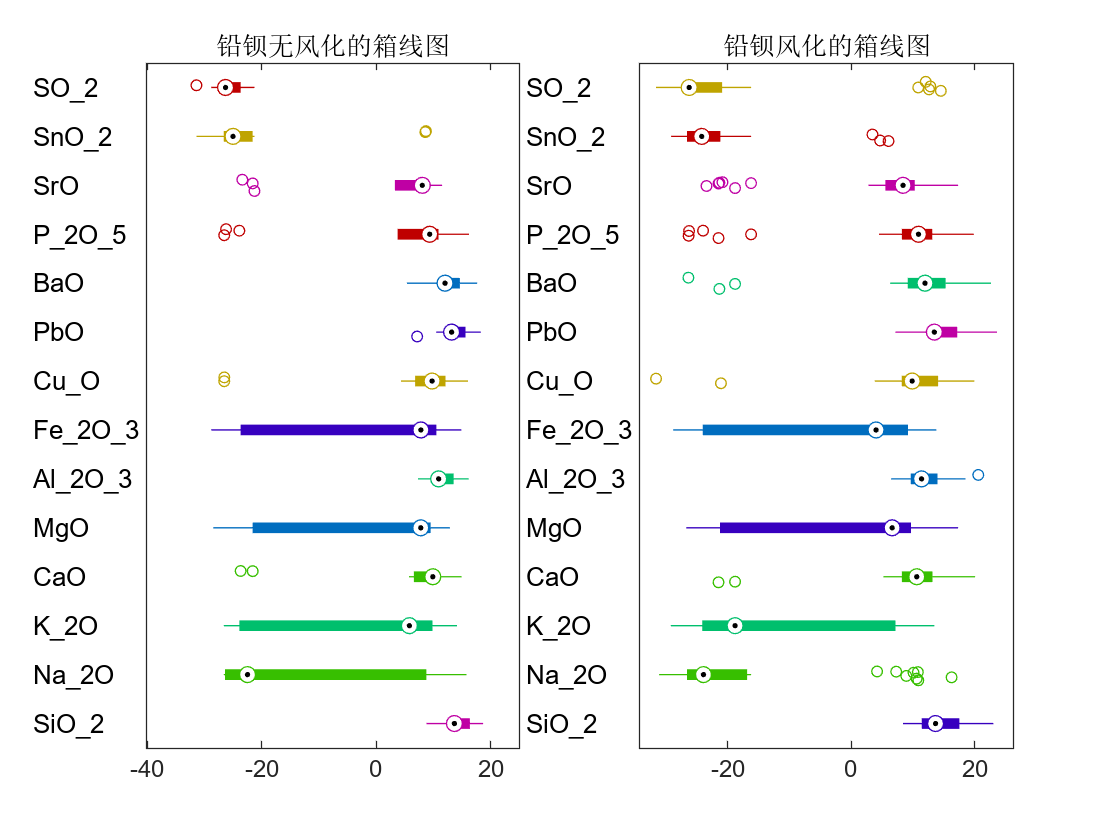

% 箱线图
subplot(121)
boxplot(Q10,'Labels',CompNames,'Orientation','horizontal','PlotStyle','compact','ColorGroup',Q10mean)
title('铅钡无风化的箱线图')
subplot(122)
boxplot(Q11,'Labels',CompNames,'Orientation','horizontal','PlotStyle','compact','ColorGroup',Q11mean)
title('铅钡风化的箱线图')

#### 5.1.3 问题 1 第 3 小问：总体抽样预测

由于缺乏风化前的数据对比，不能采用线性回归预测方法，采用总体抽样预测

未风化数据: $Q130(X) \sim N\left(\mu_X, \sigma_X^2\right)$

风化数据：$Q131(Y) \sim N\left(\mu_Y, \sigma_Y^2\right)$

预测模型：$PreQ131(Y) = \mu_X+\frac{\sigma_X}{\sigma_Y}\left(Q131(Y)-\mu_Y\right)$

% 分为未风化和风化两类，并分别计算其均值和标准差
Q130 = T2clr(Q1.WEAT == "0",:); % 已知未风化数据
Q131ind = find(Q1.WEAT == "1");
Q131 = T2clr(Q131ind,:); % 已知风化数据
Q130mean = mean(Q130);
Q130var = std(Q130);
Q131mean = mean(Q131); 
Q131var = std(Q131);
% 利用总体抽样预测
Q131clrpre = Q130mean+Q130var./Q131var./(Q131-Q131mean);
% 中心对数比逆变换的数据
Q131compre = 100*exp(Q131clrpre)./sum(exp(Q131clrpre),2)

Q131compre =    93.4075    0.0000    0.0029    0.5699    0.0000    5.9230    0.0006    0.0771    0.0116    0.0001    0.0072    0.0000    0.0000    0.0000
   92.7118    0.0000    0.0016    0.0491    0.0000    7.1032    0.0004    0.1247    0.0053    0.0000    0.0038    0.0000    0.0000    0.0000
   91.2684    0.0000    0.0059    0.2573    0.0000    7.9416    0.0011    0.4876    0.0234    0.0002    0.0144    0.0000    0.0000    0.0000
   94.9206    0.0000    0.0027    0.1041    0.0000    4.7100    0.0005    0.2447    0.0107    0.0001    0.0065    0.0000    0.0000    0.0000
   92.5546    0.0000    0.0019    0.0502    0.0000    7.2590    0.0003    0.1251    0.0051    0.0000    0.0038    0.0000    0.0000    0.0000
   92.6376    0.0000    0.0019    0.0502    0.0000    7.1752    0.0004    0.1261    0.0053    0.0000    0.0033    0.0000    0.0000    0.0000
   92.4093    0.0000    0.0028    0.3485    0.0000    6.8669    0.0005    0.3533    0.0121    0.0001    0.0065    0.0000    0.0000    0.0000


Q131tab = array2table(Q131compre,"VariableNames",CompNames);
Q131tab.NO = T2all.NO(Q131ind);
Q131tab = movevars(Q131tab,"NO",'Before',"SiO_2")

Q131tab = 42×15 table
        NO         SiO_2       Na_2O          K_2O          CaO          MgO        Al_2O_3     Fe_2O_3        Cu_O         PbO          BaO         P_2O_5         SrO          SnO_2          SO_2   
    ___________    ______    __________    __________    _________    __________    _______    __________    ________    _________    __________    _________    __________    __________    __________

    02             93.408    2.8404e-10     0.0029402      0.56994    2.4312e-05     5.923     0.00055103    0.077122     0.011558    7.4948e-05    0.0072413    2.3014e-06    7.3458e-15    3.0618e-14
    07             92.712    5.7786e-10     0.0016392     0.049126    1.3886e-05    7.1032     0.00035552     0.12474     0.005254     4.858e-05    0.0038311    1.2206e-06    6.9555e-15     2.995e-14
    08             91.268    6.0986e-10     0.0059262      0.25728    4.8465e-05    7.9416      0.0011118     0.48763     0.023412    0.00019879     0.014405     4.932e-06    1.

### 5.2 问题 2 的模型建立与求解

#### 5.2.1 问题 2 第 1 小问：玻璃的分类规律

采用中心对数比变换后的数据来决策树分类分析

分类特征：十四个特征

类别：玻璃类型

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.10526 |      1.7267 |     0.10526 |     0.10526 |            4 |
|    2 | Accept |     0.10526 |     0.20926 |     0.10526 |     0.10526 |            1 |
|    3 | Accept |     0.36842 |     0.12193 |     0.10526 |      0.1192 |            8 |
|    4 | Accept |     0.10526 |    0.094143 |     0.10526 |     0.11536 |            2 |
|    5 | Accept |     0.10526 |     0.21505 |     0.10526 |     0.10527 |            5 |
|    6 | Accept |     0.10526 |    0.051236 |     0.10526 |     0.10525 |            3 |
|    7 | Accept |     0.10526 |    0.060761 |     0.10526 |     0.10527 |            4 |
|    8 | Accept |    

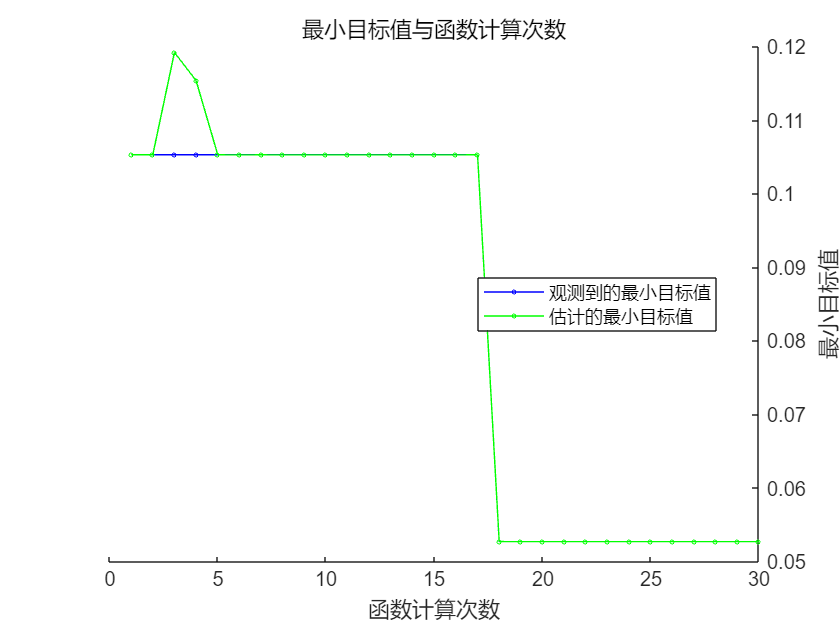

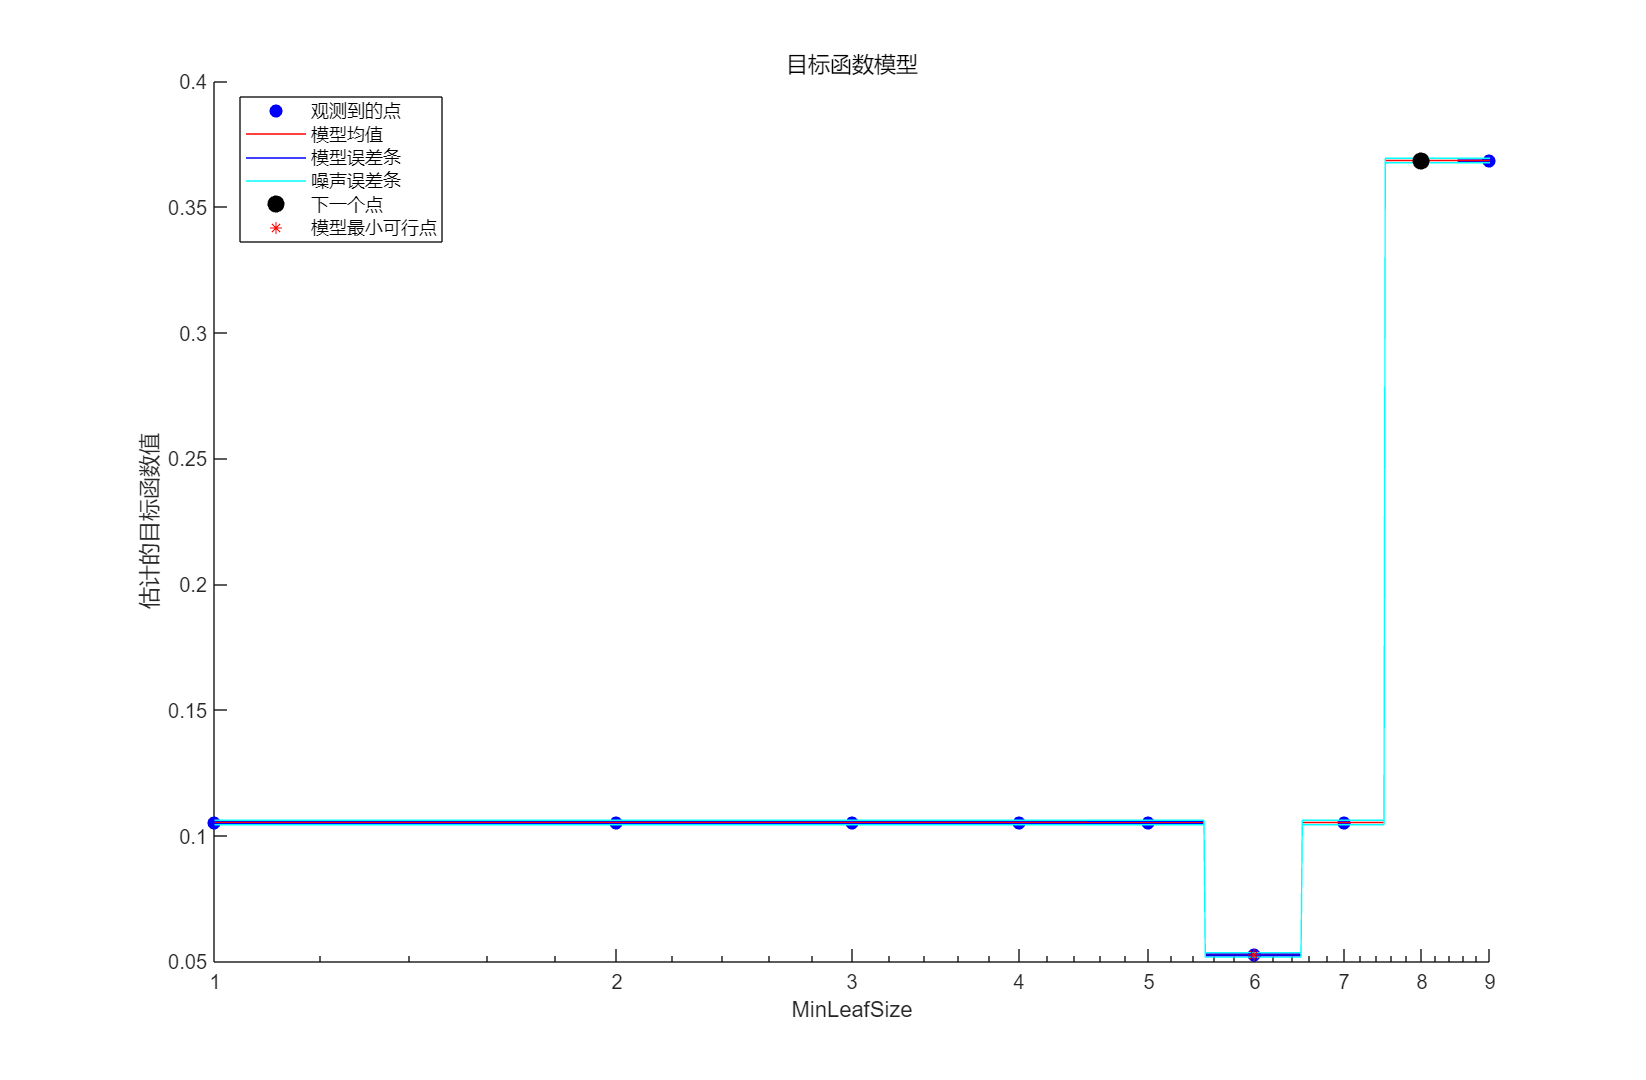


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 30。
函数计算总次数: 30
总历时: 27.2509 秒
总目标函数计算时间: 3.5829

观测到的最佳可行点:
    MinLeafSize
    ___________

         6     

观测到的目标函数值 = 0.052632
估计的目标函数值 = 0.052632
函数计算时间 = 0.044036

估计的最佳可行点(根据模型):
    MinLeafSize
    ___________

         6     

估计的目标函数值 = 0.052632
估计的函数计算时间 = 0.063553



% 无风化数据
LabelNames = cellstr(CompNames);
Q20ind = find(T2all.WEAT == "0");
Q20x = T2clr(Q20ind,:);
Q20y = T2all.TYPE(Q20ind);
Q20n = size(Q20x,1);
rng(131) % For reproducibility
Q20idxTrn = false(Q20n,1);
Q20idxTrn(randsample(Q20n,round(0.75*Q20n))) = true; 
Q20idxVal = Q20idxTrn == false;                  
Q20xtrain = Q20x(Q20idxTrn,:);%训练样本
Q20ytrain = Q20y(Q20idxTrn);%训练标签
Q20xtest = Q20x(Q20idxVal,:);%测试样本
Q20ytest = Q20y(Q20idxVal);%测试标签
Q20tree = fitctree(Q20xtrain, Q20ytrain,'PredictorNames',LabelNames,'OptimizeHyperparameters','auto'); % 创建决策树

Q20ypre = predict(Q20tree,Q20xtest);%分类结果
%验证准确度
Q20accuracy = 1-sum(~strcmp(Q20ypre,Q20ytest))/numel(Q20ypre)

Q20accuracy = 0.8333

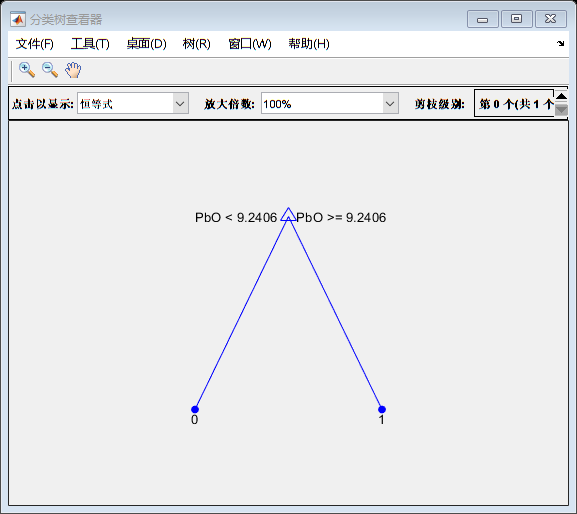

view(Q20tree,'Mode','graph'); 

% 还原成分数据
Q20class =  100*exp(9.2406)./sum(exp(Q20x(:,9)))

Q20class = 0.0079

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      0.1875 |      0.1759 |      0.1875 |      0.1875 |            7 |
|    2 | Best   |       0.125 |     0.05859 |       0.125 |     0.12916 |            2 |
|    3 | Accept |     0.15625 |    0.046064 |       0.125 |     0.12941 |            1 |
|    4 | Accept |     0.21875 |    0.056938 |       0.125 |     0.12501 |           12 |
|    5 | Accept |       0.125 |    0.048421 |       0.125 |       0.125 |            3 |
|    6 | Accept |       0.125 |    0.051498 |       0.125 |       0.125 |            2 |
|    7 | Accept |       0.125 |    0.050018 |       0.125 |       0.125 |            3 |
|    8 | Accept |    

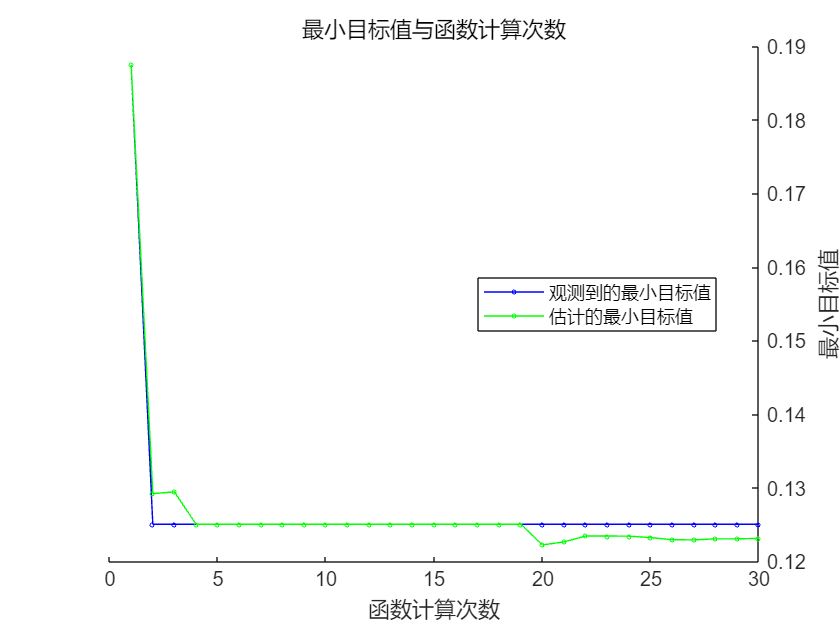

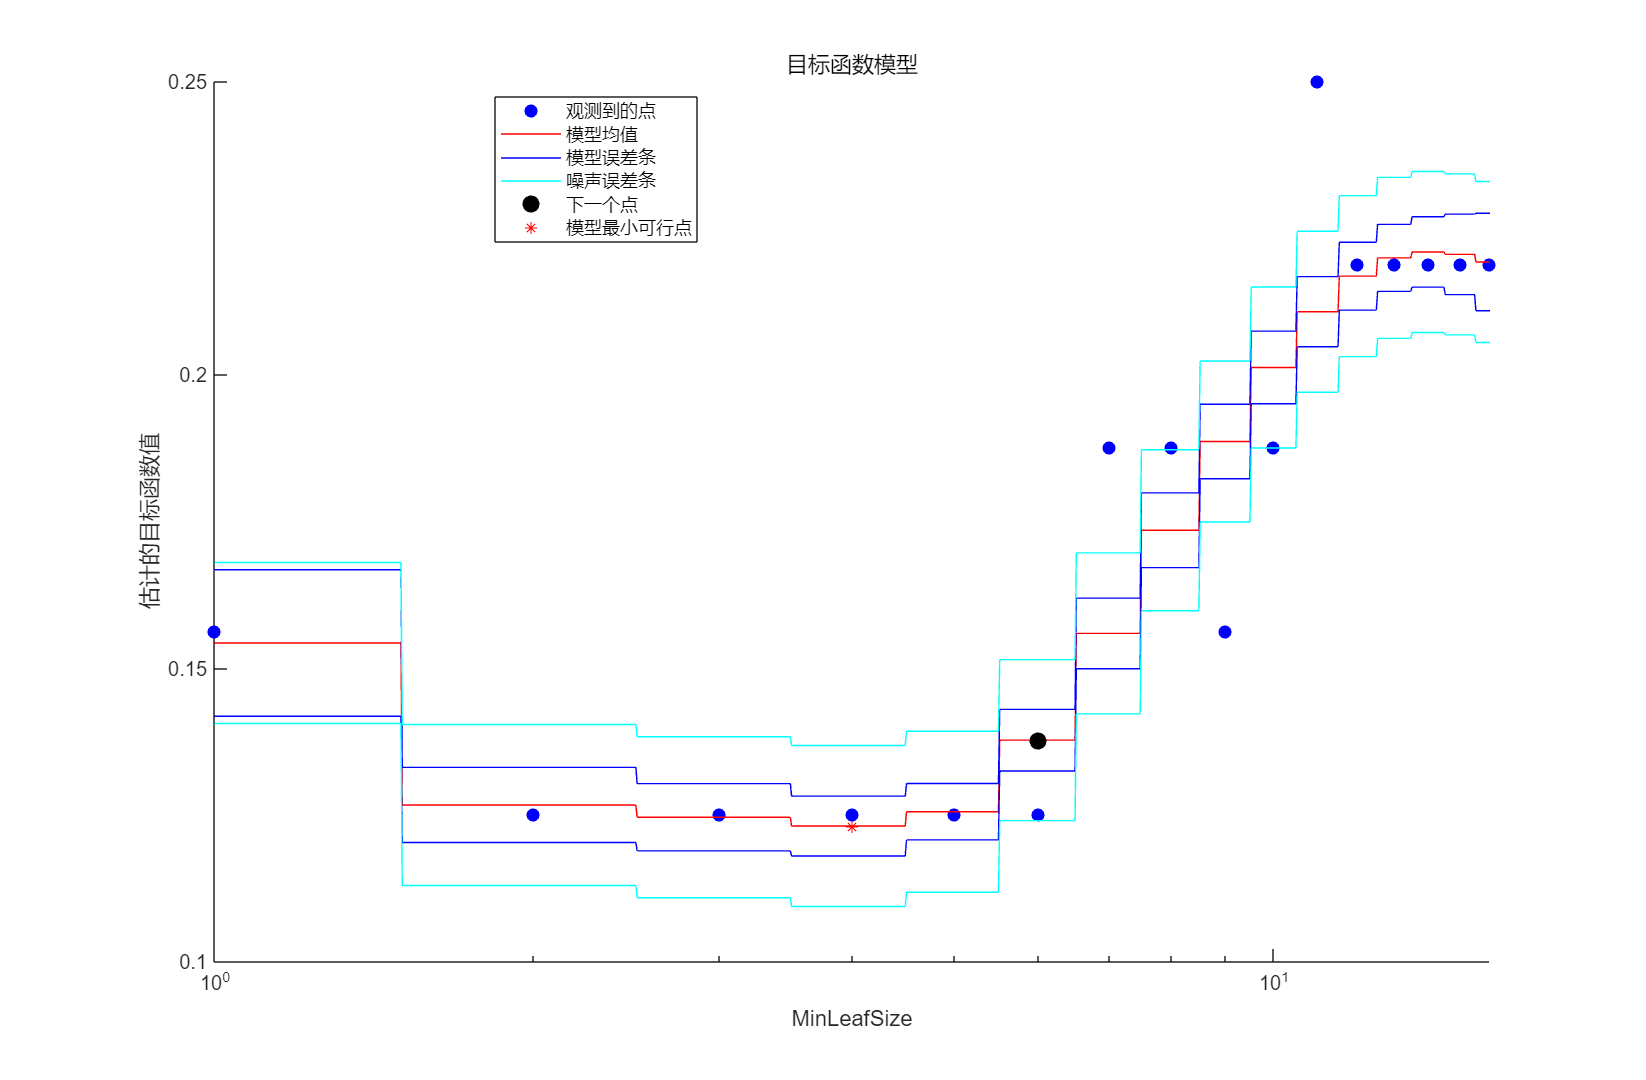


__________________________________________________________
优化完成。
达到 MaxObjectiveEvaluations 30。
函数计算总次数: 30
总历时: 17.0306 秒
总目标函数计算时间: 1.6016

观测到的最佳可行点:
    MinLeafSize
    ___________

         2     

观测到的目标函数值 = 0.125
估计的目标函数值 = 0.12667
函数计算时间 = 0.05859

估计的最佳可行点(根据模型):
    MinLeafSize
    ___________

         4     

估计的目标函数值 = 0.12308
估计的函数计算时间 = 0.051059



% 风化数据
Q21ind = find(T2all.WEAT == "1");
Q21x = T2clr(Q21ind,:);
Q21y = T2all.TYPE(Q21ind);
Q21n = size(Q21x,1);
Q21idxTrn = false(Q21n,1);
rng(1);
Q21idxTrn(randsample(Q21n,round(0.75*Q21n))) = true; 
Q21idxVal = Q21idxTrn == false;                  
Q21xtrain = Q21x(Q21idxTrn,:);%训练样本
Q21ytrain = Q21y(Q21idxTrn);%训练标签
Q21xtest = Q21x(Q21idxVal,:);%测试样本
Q21ytest = Q21y(Q21idxVal);%测试标签
Q21tree = fitctree(Q21xtrain, Q21ytrain,'PredictorNames',LabelNames,'OptimizeHyperparameters','auto'); % 创建决策树

Q21ypre = predict(Q21tree,Q21xtest);%分类结果
%验证准确度
Q21accuracy = 1-sum(~strcmp(Q21ypre,Q21ytest))/numel(Q21ypre)

Q21accuracy = 0.9000

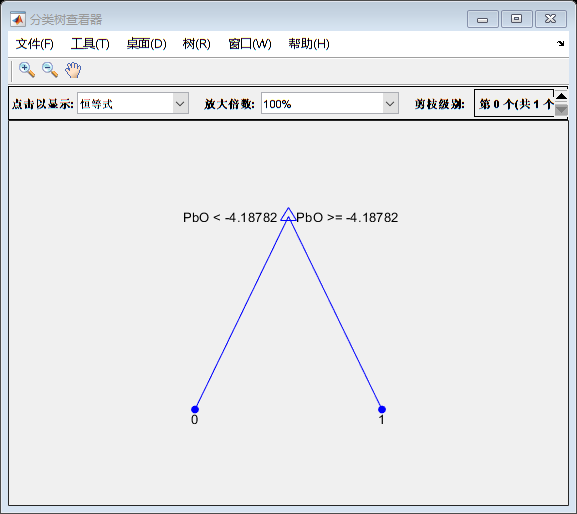

view(Q21tree,'Mode','graph'); 

% 还原成分数据
Q21class =  100*exp(-4.18782)./sum(exp(Q21x(:,9)))

Q21class = 6.9932e-11

#### 5.2.2 问题 2 第 2 小问：亚类划分

第一层次：高钾无风化、高钾风化、铅钡无风化、铅钡风化

第二层次：R 类聚类

rho =     1.0000    0.1710    0.9820    0.4073   -0.7937    0.9920   -0.2689    0.9778   -0.2446   -0.4595    0.4017   -0.6137    0.9997    0.1782
    0.1710    1.0000    0.2700    0.2804   -0.3010    0.2166    0.1163    0.1071    0.0975   -0.5281   -0.4065   -0.3254    0.1842   -0.3306
    0.9820    0.2700    1.0000    0.4435   -0.7808    0.9892   -0.2961    0.9657   -0.2630   -0.5431    0.3628   -0.6574    0.9853    0.2191
    0.4073    0.2804    0.4435    1.0000   -0.3942    0.3729   -0.1277    0.3944   -0.3186   -0.6459    0.0226   -0.5188    0.4129    0.2714
   -0.7937   -0.3010   -0.7808   -0.3942    1.0000   -0.7955    0.2690   -0.8058    0.0394    0.1432   -0.3930    0.3749   -0.7977    0.2685
    0.9920    0.2166    0.9892    0.3729   -0.7955    1.0000   -0.2945    0.9672   -0.2304   -0.4728    0.4142   -0.6269    0.9937    0.1745
   -0.2689    0.1163   -0.2961   -0.1277    0.2690   -0.2945    1.0000   -0.1754   -0.6017   -0.0387   -0.0999    0.0179   -0.2629    0.1692
    0.9

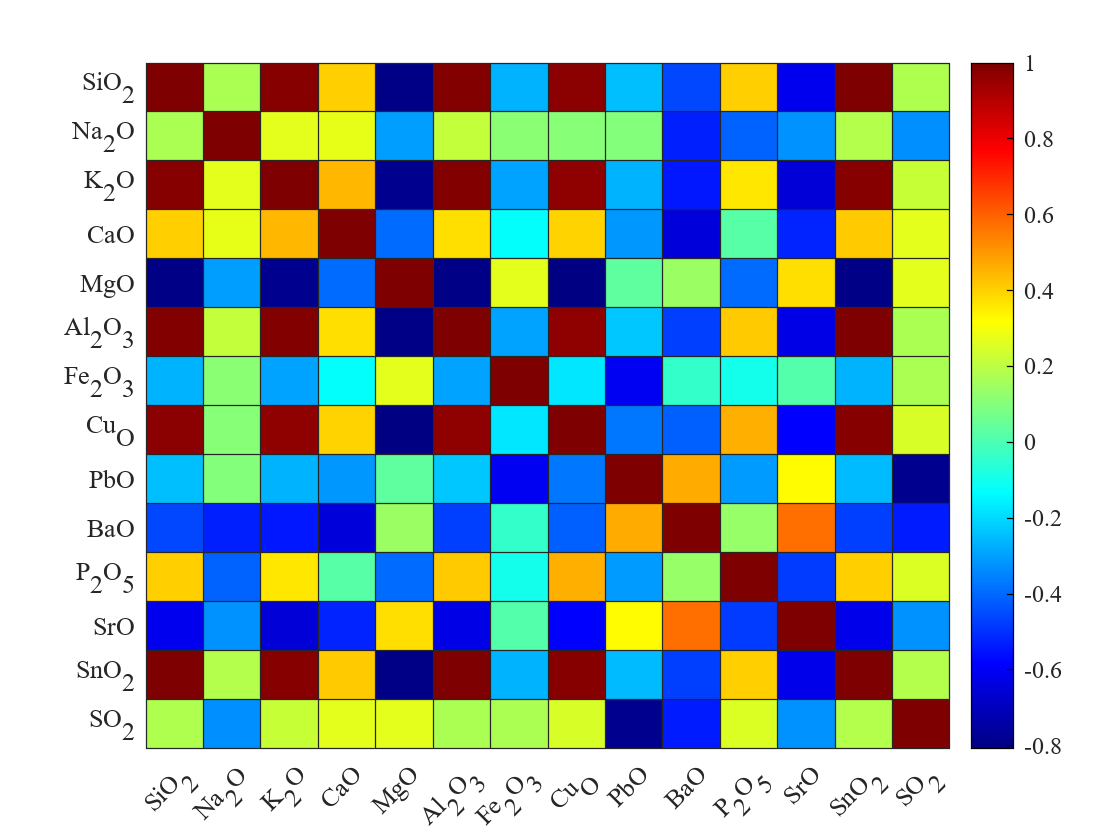

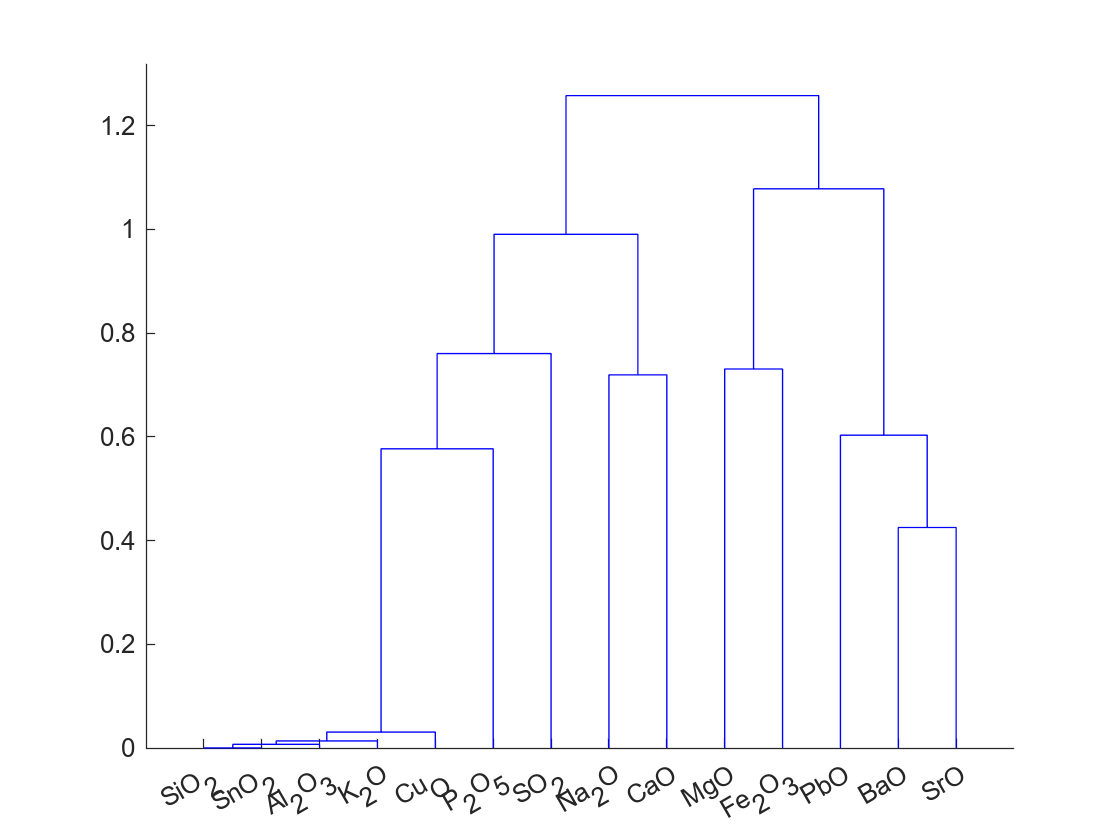

ans = 14×2 table
      成分       分类
    _________    ____

    "PbO"         1  
    "BaO"         1  
    "SrO"         1  
    "MgO"         2  
    "Fe_2O_3"     2  
    "SiO_2"       3  
    "Na_2O"       3  
    "K_2O"        3  
    "CaO"         3  
    "Al_2O_3"     3  
    "Cu_O"        3  
    "P_2O_5"      3  
    "SnO_2"       3  
    "SO_2"        3  


% 高钾无风化情况 
clusterR(Q00)

rho =     1.0000    0.9998    0.3320    0.1413   -0.6289    0.9876    0.1488    0.1895   -0.6950   -0.6974   -0.2952    0.2353    0.2151    0.9998
    0.9998    1.0000    0.3299    0.1242   -0.6238    0.9895    0.1318    0.1729   -0.6891   -0.6915   -0.2920    0.2523    0.2322    1.0000
    0.3320    0.3299    1.0000   -0.3550   -0.2109    0.2597   -0.3304   -0.3449   -0.5911   -0.5907   -0.3680    0.4472    0.4424    0.3299
    0.1413    0.1242   -0.3550    1.0000   -0.5019    0.0687    0.9986    0.9982    0.0872    0.0863   -0.2414   -0.9282   -0.9357    0.1242
   -0.6289   -0.6238   -0.2109   -0.5019    1.0000   -0.5492   -0.5227   -0.5416    0.1593    0.1617    0.3447    0.2595    0.2742   -0.6238
    0.9876    0.9895    0.2597    0.0687   -0.5492    1.0000    0.0704    0.1158   -0.6911   -0.6935   -0.1993    0.3066    0.2870    0.9895
    0.1488    0.1318   -0.3304    0.9986   -0.5227    0.0704    1.0000    0.9982    0.0978    0.0969   -0.2845   -0.9255   -0.9331    0.1318
    0.1

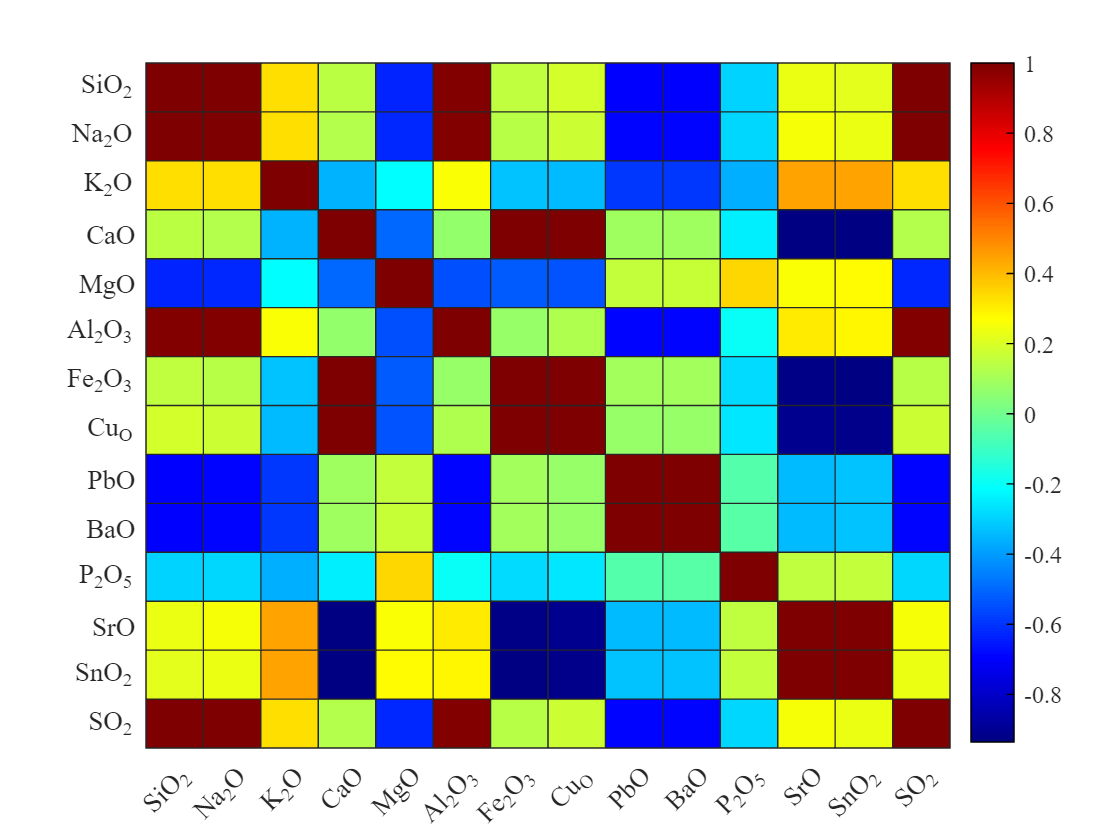

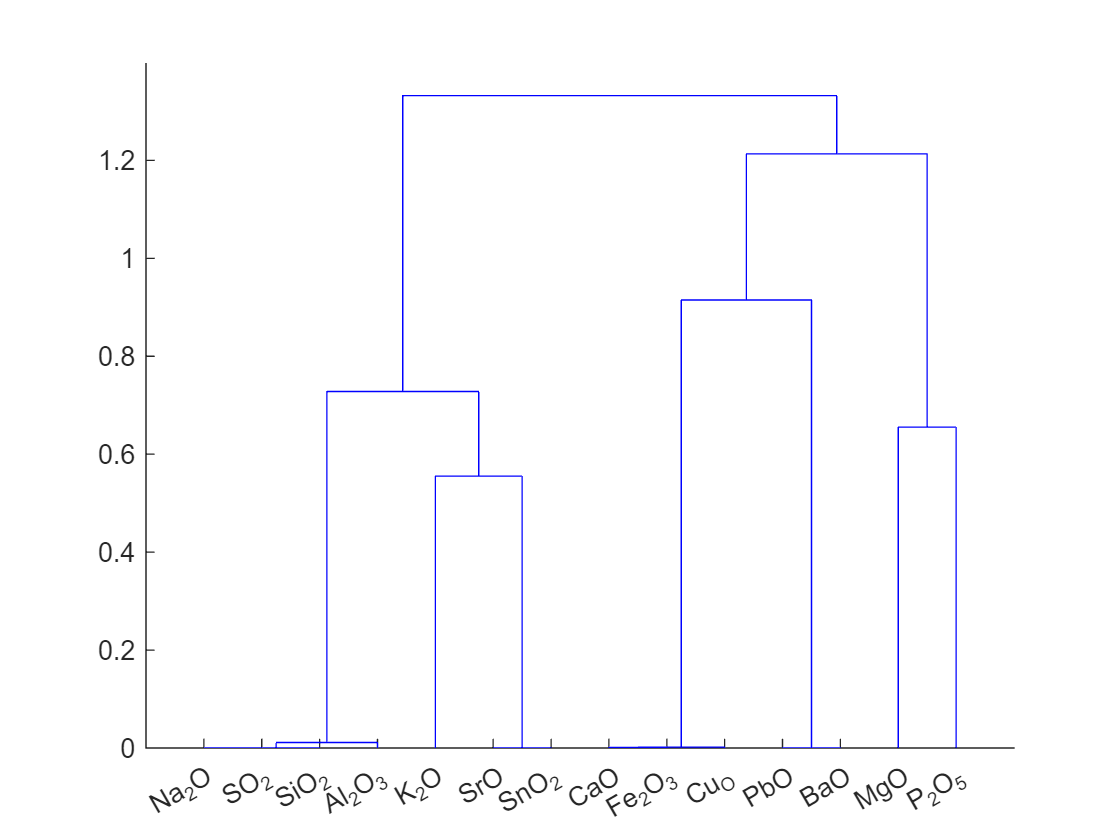

ans = 14×2 table
      成分       分类
    _________    ____

    "MgO"         1  
    "P_2O_5"      1  
    "CaO"         2  
    "Fe_2O_3"     2  
    "Cu_O"        2  
    "PbO"         2  
    "BaO"         2  
    "SiO_2"       3  
    "Na_2O"       3  
    "K_2O"        3  
    "Al_2O_3"     3  
    "SrO"         3  
    "SnO_2"       3  
    "SO_2"        3  


% 高钾风化情况 
clusterR(Q01)

rho =     1.0000   -0.0980   -0.0535   -0.3003   -0.2927    0.9731   -0.1558    0.3593    0.9673    0.9728    0.1516   -0.6143    0.0619    0.9951
   -0.0980    1.0000   -0.0357    0.2575   -0.0453   -0.1892   -0.6853    0.3339   -0.1706   -0.1135   -0.3366   -0.0324   -0.4117   -0.1334
   -0.0535   -0.0357    1.0000   -0.4688   -0.3425    0.0013    0.0060    0.0888   -0.0992   -0.0070   -0.0909   -0.1844   -0.1387   -0.0632
   -0.3003    0.2575   -0.4688    1.0000    0.0083   -0.4221    0.0457   -0.2720   -0.2339   -0.3462   -0.3057    0.1123    0.1323   -0.3046
   -0.2927   -0.0453   -0.3425    0.0083    1.0000   -0.2219   -0.3430   -0.3418   -0.3345   -0.3154   -0.4466    0.6570    0.2324   -0.3089
    0.9731   -0.1892    0.0013   -0.4221   -0.2219    1.0000   -0.0886    0.2924    0.9333    0.9553    0.1673   -0.6220    0.1292    0.9745
   -0.1558   -0.6853    0.0060    0.0457   -0.3430   -0.0886    1.0000   -0.3180   -0.1008   -0.1425    0.3459   -0.1990    0.2859   -0.1177
    0.3

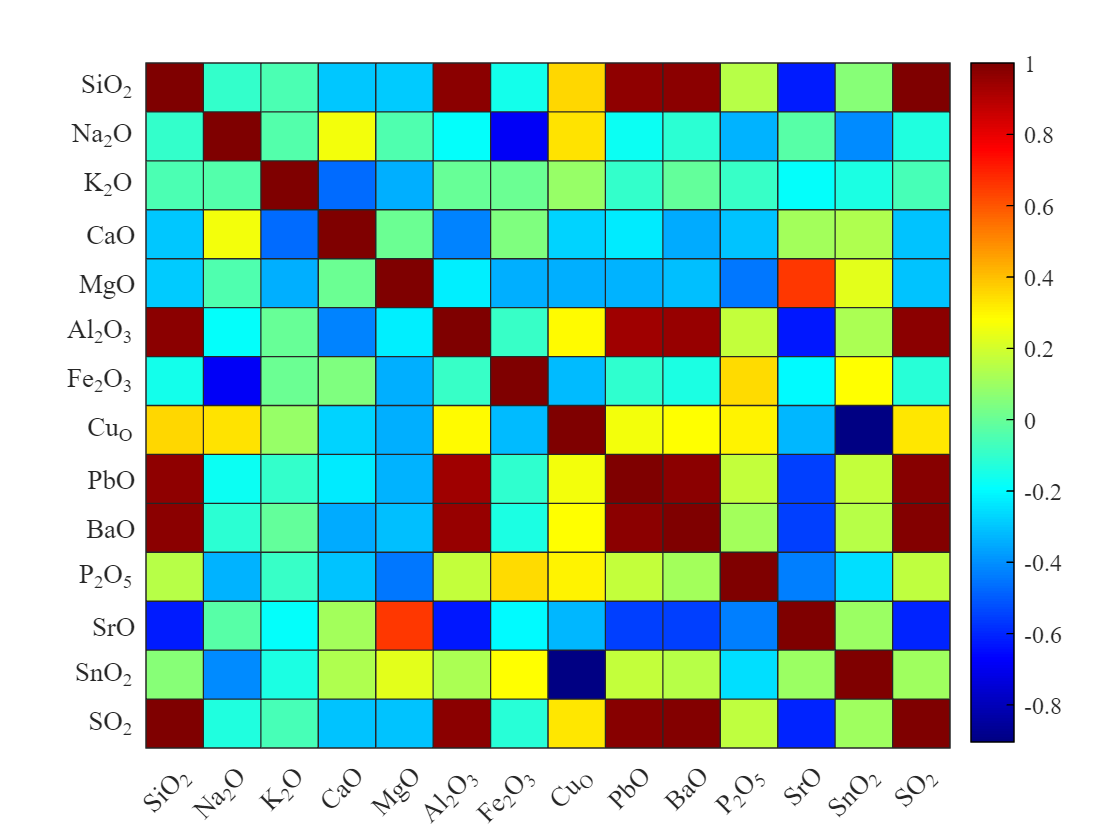

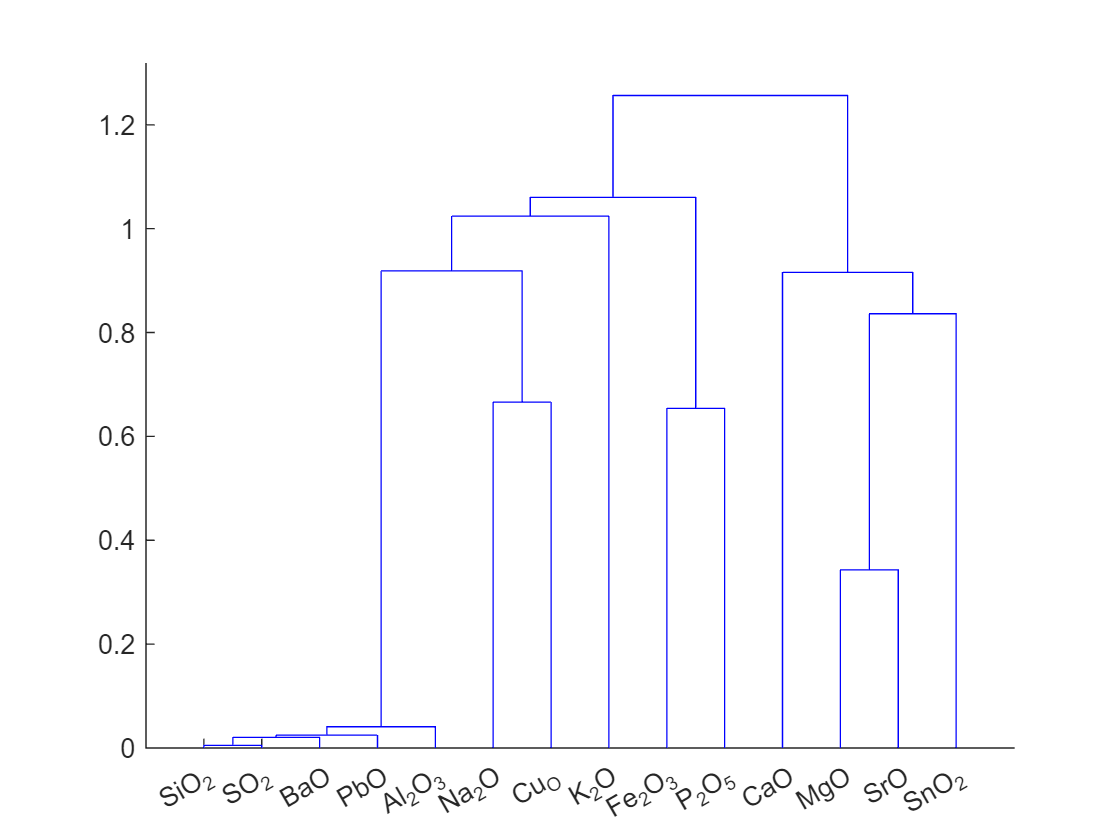

ans = 14×2 table
      成分       分类
    _________    ____

    "Fe_2O_3"     1  
    "P_2O_5"      1  
    "SiO_2"       2  
    "Na_2O"       2  
    "K_2O"        2  
    "Al_2O_3"     2  
    "Cu_O"        2  
    "PbO"         2  
    "BaO"         2  
    "SO_2"        2  
    "CaO"         3  
    "MgO"         3  
    "SrO"         3  
    "SnO_2"       3  


% 铅钡无风化情况 
clusterR(Q10)

rho =     1.0000    0.0219   -0.2774    0.0375   -0.2399    0.9792   -0.2627    0.4484    0.9636    0.1039   -0.0311   -0.4287   -0.0922    0.1692
    0.0219    1.0000    0.0974   -0.3275   -0.0964    0.0063   -0.0057   -0.1459   -0.0834    0.0949   -0.5169   -0.1152   -0.0585   -0.2351
   -0.2774    0.0974    1.0000   -0.2833    0.2386   -0.2499   -0.2677   -0.1645   -0.3885   -0.1266   -0.3251   -0.1657   -0.0760   -0.1095
    0.0375   -0.3275   -0.2833    1.0000   -0.3910   -0.0201    0.1145   -0.0121    0.0759    0.2914    0.1610   -0.0072   -0.1125    0.1177
   -0.2399   -0.0964    0.2386   -0.3910    1.0000   -0.1726    0.1444   -0.0685   -0.2521   -0.4553   -0.1004   -0.1266    0.0802   -0.5925
    0.9792    0.0063   -0.2499   -0.0201   -0.1726    1.0000   -0.2553    0.4590    0.9624    0.0352   -0.0833   -0.4162   -0.0728    0.1698
   -0.2627   -0.0057   -0.2677    0.1145    0.1444   -0.2553    1.0000   -0.3625   -0.2320   -0.2863   -0.0200   -0.0317    0.1360   -0.5104
    0.4

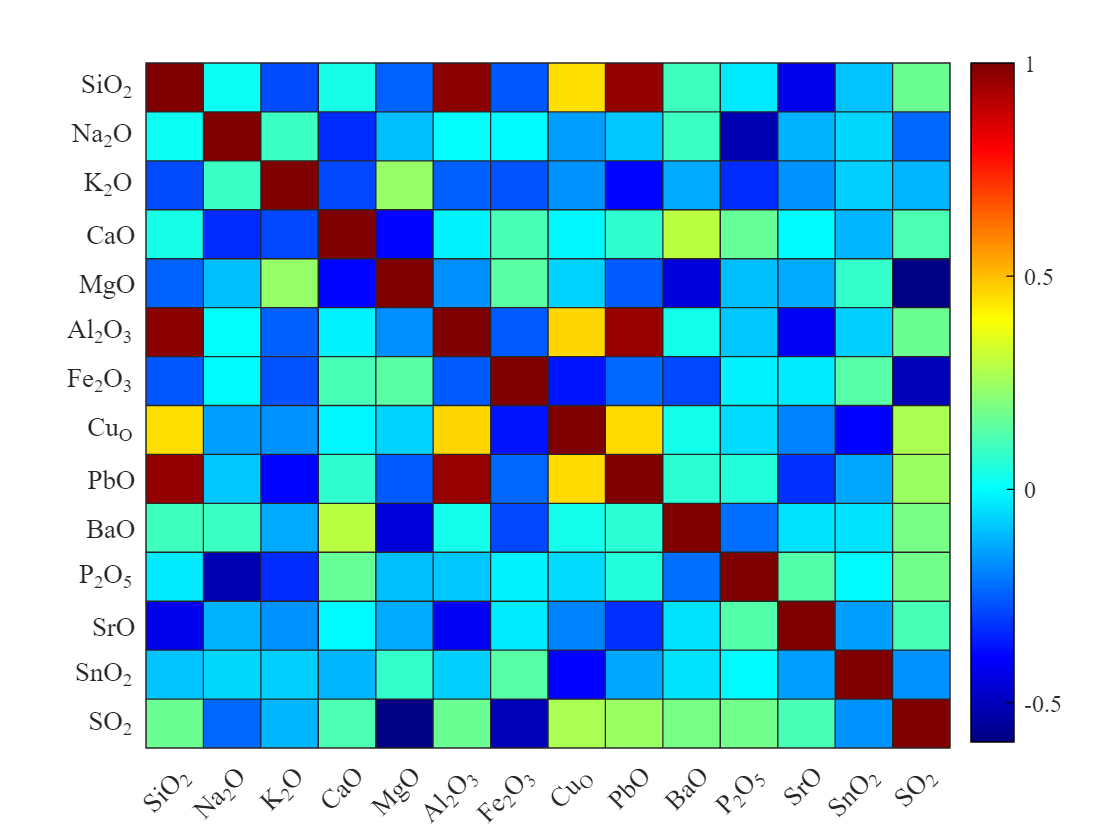

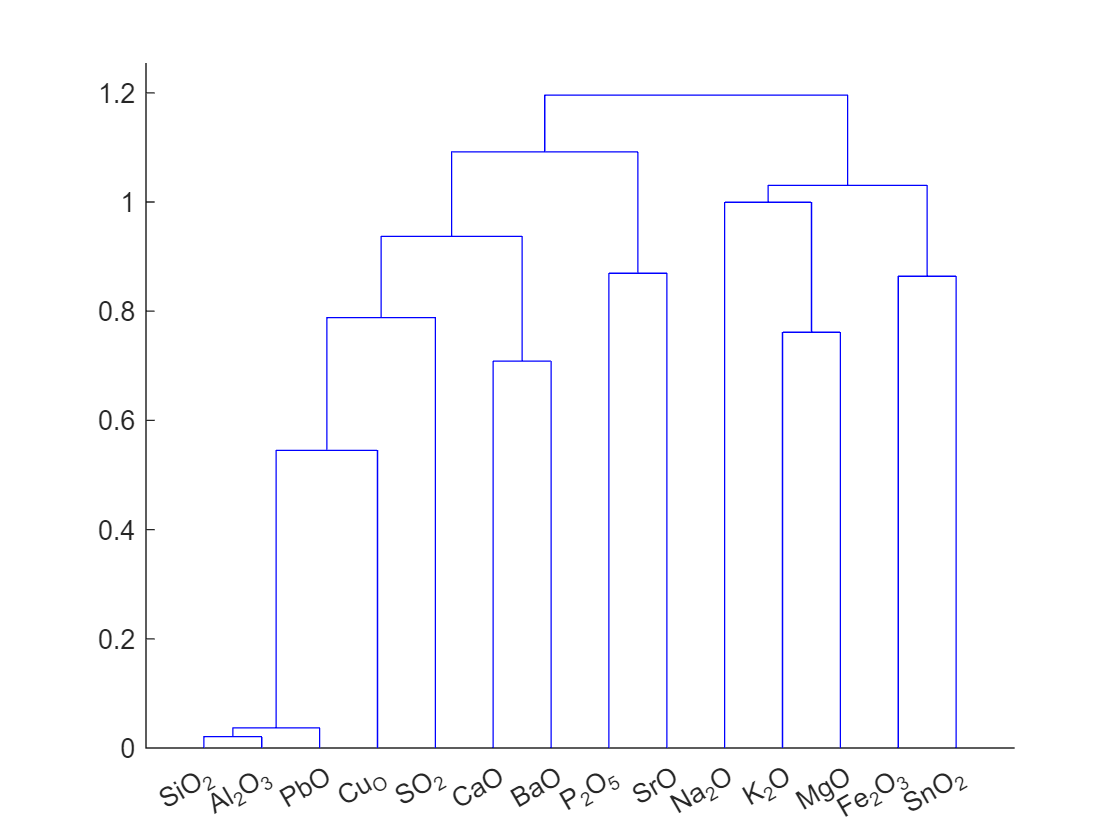

ans = 14×2 table
      成分       分类
    _________    ____

    "P_2O_5"      1  
    "SrO"         1  
    "SiO_2"       2  
    "CaO"         2  
    "Al_2O_3"     2  
    "Cu_O"        2  
    "PbO"         2  
    "BaO"         2  
    "SO_2"        2  
    "Na_2O"       3  
    "K_2O"        3  
    "MgO"         3  
    "Fe_2O_3"     3  
    "SnO_2"       3  


% 铅钡风化情况 
clusterR(Q11)

#### 5.2.3 问题 2 第 3 小问：合理性和敏感性

合理性：先确定四个子类，再根据相关系数获取特征间的相互系数，利用聚类分析对相近成分分类，合理可行。

敏感性分析：对原数据赋予小扰动，看看结果的波动情况

rho =     1.0000    0.1710    0.9820    0.4073   -0.7937    0.9920   -0.2689    0.9778   -0.2446   -0.4595    0.4017   -0.6137    0.9997    0.1782
    0.1710    1.0000    0.2700    0.2804   -0.3010    0.2166    0.1163    0.1071    0.0975   -0.5281   -0.4065   -0.3254    0.1842   -0.3306
    0.9820    0.2700    1.0000    0.4435   -0.7808    0.9892   -0.2961    0.9657   -0.2630   -0.5431    0.3628   -0.6574    0.9853    0.2191
    0.4073    0.2804    0.4435    1.0000   -0.3942    0.3729   -0.1277    0.3944   -0.3186   -0.6459    0.0226   -0.5188    0.4129    0.2714
   -0.7937   -0.3010   -0.7808   -0.3942    1.0000   -0.7955    0.2690   -0.8058    0.0394    0.1432   -0.3930    0.3749   -0.7977    0.2685
    0.9920    0.2166    0.9892    0.3729   -0.7955    1.0000   -0.2945    0.9672   -0.2304   -0.4728    0.4142   -0.6269    0.9937    0.1745
   -0.2689    0.1163   -0.2961   -0.1277    0.2690   -0.2945    1.0000   -0.1754   -0.6017   -0.0387   -0.0999    0.0179   -0.2629    0.1692
    0.9

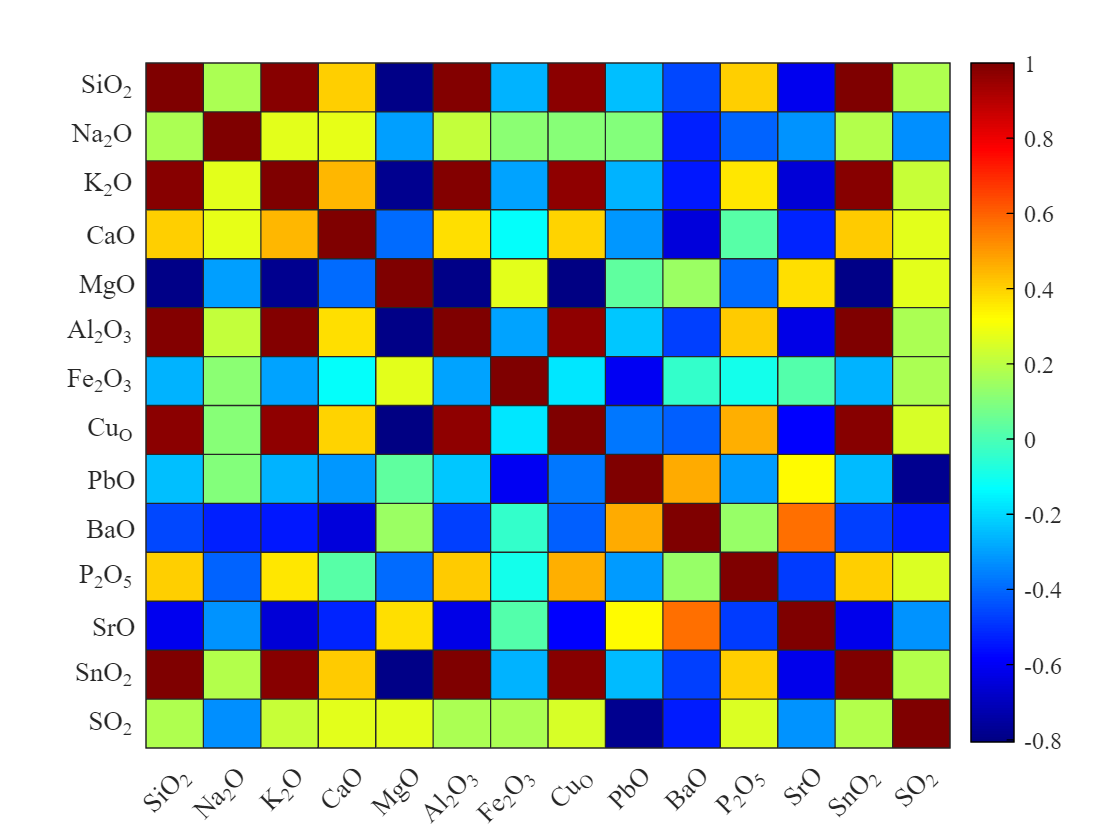

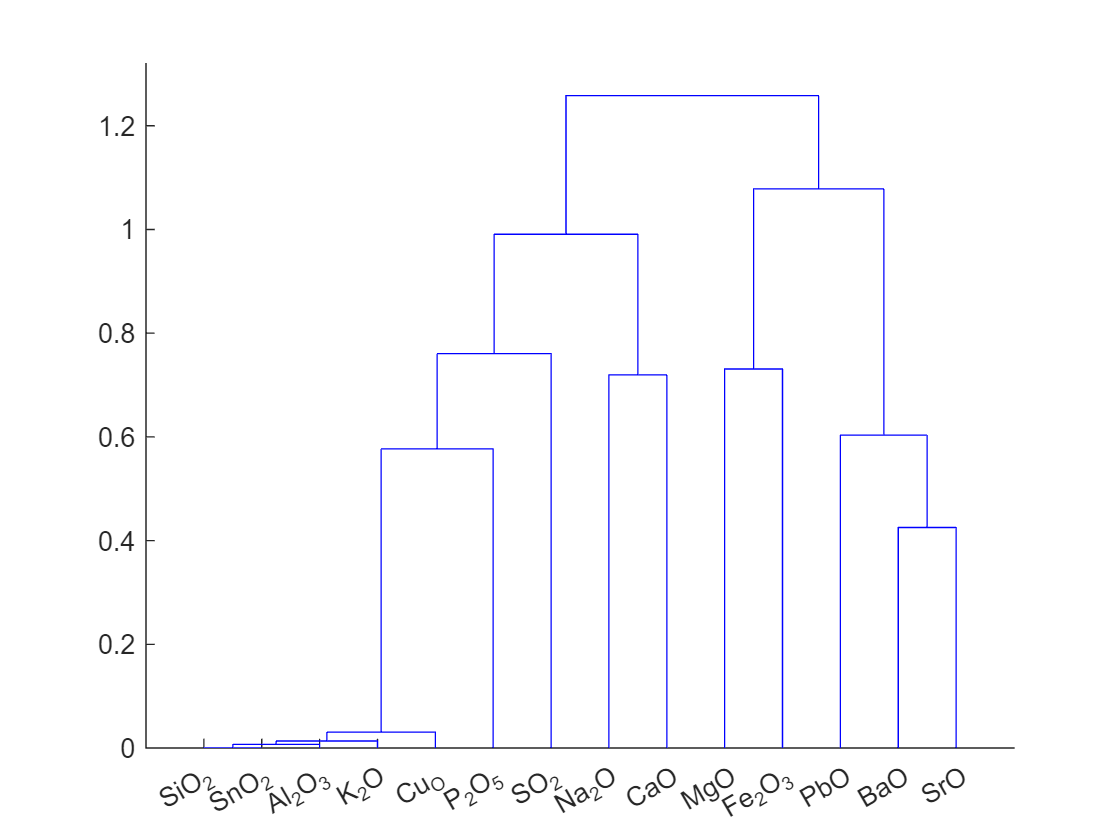

ans = 14×2 table
      成分       分类
    _________    ____

    "PbO"         1  
    "BaO"         1  
    "SrO"         1  
    "MgO"         2  
    "Fe_2O_3"     2  
    "SiO_2"       3  
    "Na_2O"       3  
    "K_2O"        3  
    "CaO"         3  
    "Al_2O_3"     3  
    "Cu_O"        3  
    "P_2O_5"      3  
    "SnO_2"       3  
    "SO_2"        3  


% 高钾无风化的敏感性分析 
clusterR(Q00+0.01)

分类不变，其他情况类似分析

### 5.3 问题 3 的模型建立和求解

利用第 2 问训练好的决策树预测

#### 5.3.1 类属预测

% 利用决策树预测
% 无风化情形
Q30ind = T3all.WEAT == "0";
Q30 = T3clr(Q30ind,:);
Q30NO = T3all.NO(Q30ind)

Q30NO = 4×1 categorical 数组
     A1 
     A3 
     A4 
     A8 


predict(Q20tree,Q30)

ans = 4×1 categorical 数组
     0 
     1 
     1 
     1 


高钾：A1

铅钡：A3、A4、A8

% 风化情形
Q31ind = T3all.WEAT == "1";
Q31 = T3clr(Q31ind,:);
Q31NO = T3all.NO(Q31ind)

Q31NO = 4×1 categorical 数组
     A2 
     A5 
     A6 
     A7 


predict(Q21tree,Q31)

ans = 4×1 categorical 数组
     1 
     1 
     0 
     0 


高钾：A6、A7

铅钡：A2、A5

#### 5.3.2 敏感性分析

% 无风化情况
predict(Q20tree,Q30+0.1)

ans = 4×1 categorical 数组
     0 
     1 
     1 
     1 


% 风化情况
predict(Q21tree,Q31+0.1)

ans = 4×1 categorical 数组
     1 
     1 
     0 
     0 


### 5.4 问题 4 的模型建立和求解

成分之间的关联和差异度，采用 Pearson 相关系数分析+灰色关联度分析

% 数据分类
Q30 = T2clr(Q1.TYPE == "0",:); % 高钾
Q31 = T2clr(Q1.TYPE == "1",:); % 铅钡

#### 5.4.1 关联分析

% Pearson 相关系数
Q30rho = corr(Q30, 'type','pearson')

Q30rho =     1.0000    0.0532   -0.0496    0.2995   -0.5339    0.9941    0.0096    0.2832   -0.4307   -0.3638    0.2300   -0.3833    0.5906    0.0679
    0.0532    1.0000    0.1527    0.2022   -0.2664    0.0885    0.0686    0.0514    0.0849   -0.4936   -0.3533   -0.2169   -0.0092   -0.2784
   -0.0496    0.1527    1.0000   -0.1827   -0.2361   -0.0634   -0.3055   -0.2387   -0.1607   -0.3759   -0.2134    0.1885    0.1421    0.1407
    0.2995    0.2022   -0.1827    1.0000   -0.4399    0.2700    0.4219    0.7092   -0.2074   -0.3840   -0.0684   -0.6688   -0.3499    0.1974
   -0.5339   -0.2664   -0.2361   -0.4399    1.0000   -0.5235   -0.1379   -0.5428    0.0731    0.1461   -0.0684    0.3192   -0.0016    0.1308
    0.9941    0.0885   -0.0634    0.2700   -0.5235    1.0000   -0.0322    0.2609   -0.4178   -0.3769    0.2669   -0.3890    0.6055    0.0706
    0.0096    0.0686   -0.3055    0.4219   -0.1379   -0.0322    1.0000    0.6576   -0.3458    0.0200   -0.1613   -0.3862   -0.5320    0.1054
    

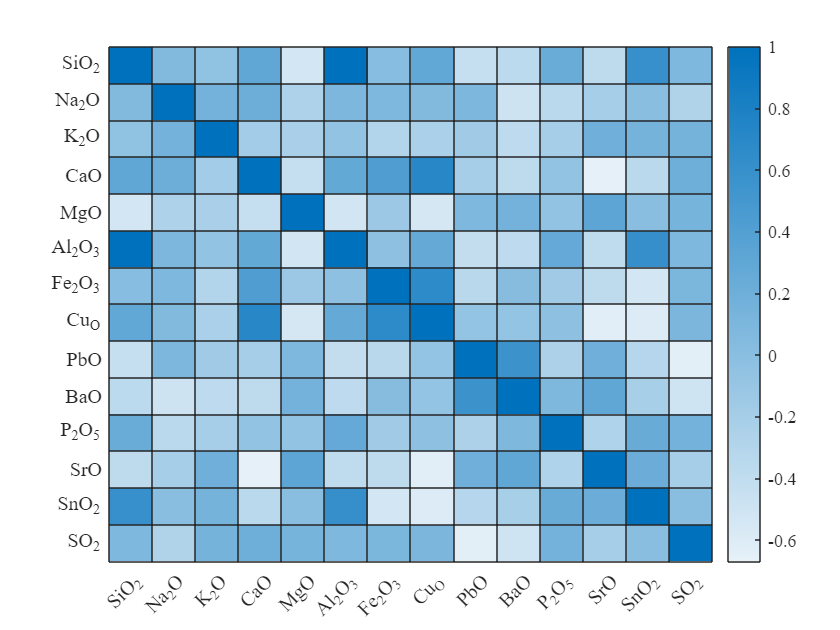

% 热图
figure;
heatmap(LabelNames,LabelNames,Q30rho, 'FontSize',10, 'FontName','Times New Roman');

colormap(jet)

% Pearson 相关系数
Q31rho = corr(Q31, 'type','pearson')

Q31rho =     1.0000   -0.0140   -0.2215   -0.0580   -0.2510    0.9772   -0.2364    0.4044    0.9594    0.1643    0.0201   -0.4655   -0.0457    0.2045
   -0.0140    1.0000    0.0878   -0.1217   -0.0742   -0.0564   -0.1999    0.0121   -0.1232    0.0839   -0.4673   -0.1019   -0.1835   -0.2310
   -0.2215    0.0878    1.0000   -0.3737    0.0718   -0.1966   -0.1591   -0.1005   -0.3331   -0.0786   -0.2689   -0.1848   -0.0844   -0.1345
   -0.0580   -0.1217   -0.3737    1.0000   -0.2400   -0.1209    0.0620   -0.0909    0.0101    0.1392    0.0018    0.0557   -0.0147    0.1030
   -0.2510   -0.0742    0.0718   -0.2400    1.0000   -0.1838    0.0068   -0.1644   -0.2682   -0.4042   -0.2106    0.1067    0.1335   -0.5100
    0.9772   -0.0564   -0.1966   -0.1209   -0.1838    1.0000   -0.2199    0.3990    0.9559    0.0966   -0.0069   -0.4529   -0.0162    0.2133
   -0.2364   -0.1999   -0.1591    0.0620    0.0068   -0.2199    1.0000   -0.3549   -0.2113   -0.2328    0.0795   -0.0926    0.1937   -0.4456
    

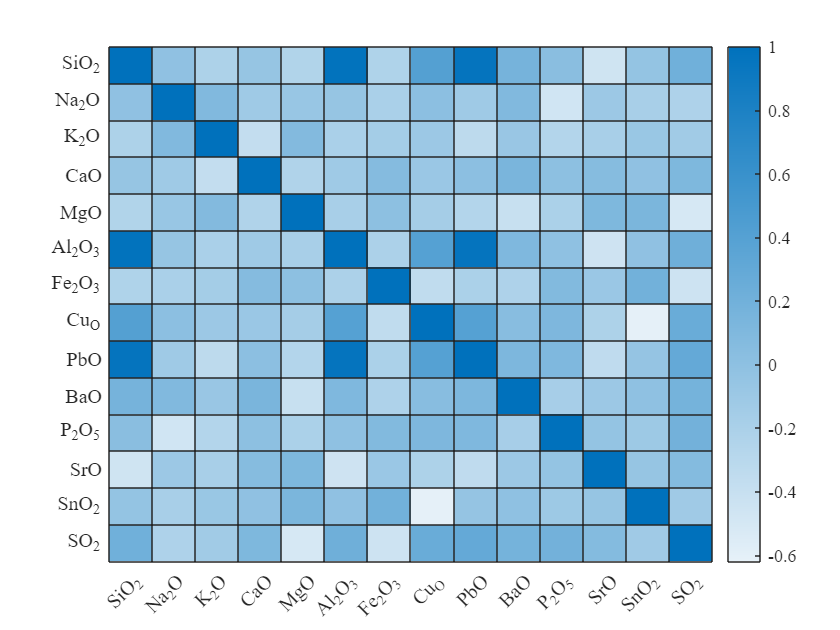

% 热图
figure;
heatmap(LabelNames,LabelNames,Q31rho, 'FontSize',10, 'FontName','Times New Roman');

colormap(jet)

Q30R = GRA(Q30(:,1),Q30(:,2:end));
Q31R = GRA(Q31(:,1),Q31(:,2:end));

% 氧化硅与其他成分的关联度分析，其他成分类似分析
Q3tab = table(Q30R,Q31R,'VariableNames',["高钾类","铅钡类"]);
Q3tab.Properties.RowNames = CompNames(2:end)

Q3tab = 13×2 table
                高钾类      铅钡类 
               _______    _______

    Na_2O      0.91016     0.8248
    K_2O       0.86752    0.70393
    CaO         0.9142    0.89207
    MgO        0.48781    0.48835
    Al_2O_3    0.99668    0.98852
    Fe_2O_3    0.91354     0.6033
    Cu_O       0.96046     0.8825
    PbO        0.81716    0.98594
    BaO        0.91034    0.92645
    P_2O_5     0.91044    0.73713
    SrO        0.87435    0.65059
    SnO_2      0.92843    0.91446
    SO_2       0.91311    0.89894


#### 5.4.2 差异分析

Wilcoxon 秩和检验

$H_0:$ 高钾玻璃和铅钡玻璃的化学成分没有显著差异

$H_1:$ 高钾玻璃和铅钡玻璃的化学成分存在显著差异

Q30rhotriu = triu(Q30rho,1)

Q30rhotriu =          0    0.0532   -0.0496    0.2995   -0.5339    0.9941    0.0096    0.2832   -0.4307   -0.3638    0.2300   -0.3833    0.5906    0.0679
         0         0    0.1527    0.2022   -0.2664    0.0885    0.0686    0.0514    0.0849   -0.4936   -0.3533   -0.2169   -0.0092   -0.2784
         0         0         0   -0.1827   -0.2361   -0.0634   -0.3055   -0.2387   -0.1607   -0.3759   -0.2134    0.1885    0.1421    0.1407
         0         0         0         0   -0.4399    0.2700    0.4219    0.7092   -0.2074   -0.3840   -0.0684   -0.6688   -0.3499    0.1974
         0         0         0         0         0   -0.5235   -0.1379   -0.5428    0.0731    0.1461   -0.0684    0.3192   -0.0016    0.1308
         0         0         0         0         0         0   -0.0322    0.2609   -0.4178   -0.3769    0.2669   -0.3890    0.6055    0.0706
         0         0         0         0         0         0         0    0.6576   -0.3458    0.0200   -0.1613   -0.3862   -0.5320    0.1054


Q31rhotriu = triu(Q31rho,1)

Q31rhotriu =          0   -0.0140   -0.2215   -0.0580   -0.2510    0.9772   -0.2364    0.4044    0.9594    0.1643    0.0201   -0.4655   -0.0457    0.2045
         0         0    0.0878   -0.1217   -0.0742   -0.0564   -0.1999    0.0121   -0.1232    0.0839   -0.4673   -0.1019   -0.1835   -0.2310
         0         0         0   -0.3737    0.0718   -0.1966   -0.1591   -0.1005   -0.3331   -0.0786   -0.2689   -0.1848   -0.0844   -0.1345
         0         0         0         0   -0.2400   -0.1209    0.0620   -0.0909    0.0101    0.1392    0.0018    0.0557   -0.0147    0.1030
         0         0         0         0         0   -0.1838    0.0068   -0.1644   -0.2682   -0.4042   -0.2106    0.1067    0.1335   -0.5100
         0         0         0         0         0         0   -0.2199    0.3990    0.9559    0.0966   -0.0069   -0.4529   -0.0162    0.2133
         0         0         0         0         0         0         0   -0.3549   -0.2113   -0.2328    0.0795   -0.0926    0.1937   -0.4456


[Q3p,Q3h] = signrank(Q30rhotriu(:),Q31rhotriu(:))

Q3p = 0.9590

Q3h = logical
   0


结论：不拒绝原假设，即高钾玻璃和铅钡玻璃的化学成分没有显著差异。